# Machine Learning: Programming Exercise 5

## Regularized Linear Regression and Bias vs. Variance

In this exercise, you will implement regularized linear regression and use it to study models with different bias-variance properties.

### Files needed for this exercise

- `ex5.mlx` - MATLAB Live Script that steps you through the exercise

- `ex5data1.mat` - Dataset

- `submit.m` - Submission script that sends your solutions to our servers

- `featureNormalize.m` - Feature normalization function

- `fmincg.m` - Function minimization routine (similar to `fminunc`)

- `plotFit.m` - Plot a polynomial fit

- `trainLinearReg.m` - Trains linear regression using your cost function

- *`linearRegCostFunction.m` - Regularized linear regression cost function

- `*learningCurve.m` - Generates a learning curve

- *`polyFeatures.m` - Maps data into polynomial feature space

- *`validationCurve.m` - Generates a cross validation curve

****indicates files you will need to complete***

#### Clear existing variables and confirm that your Current Folder is set correctly

Click into this section, then click the 'Run Section' button above. This will execute the `clear` command to clear existing variables and the `dir` command to list the files in your Current Folder. The output should contain all of the files listed above and the 'lib' folder. If it does not, right-click the 'ex5' folder and select 'Open' before proceding or see the instructions in `README.mlx` for more details.

clear
dir

### Before you begin

The workflow for completing and submitting the programming exercises in MATLAB Online differs from the original course instructions. Before beginning this exercise, make sure you have read through the instructions in `README.mlx` which is included with the programming exercise files. `README` also contains solutions to the many common issues you may encounter while completing and submitting the exercises in MATLAB Online. Make sure you are following instructions in `README` and have checked for an existing solution before seeking help on the discussion forums.

## 1. Regularized Linear Regression

In the first half of the exercise, you will implement regularized linear regression to predict the amount of water flowing out of a dam using the change of water level in a reservoir. In the next half, you will go through some diagnostics of debugging learning algorithms and examine the effects of bias vs. variance.

### 1.1 Visualizing the dataset

We will begin by visualizing the dataset containing historical records on the change in the water level, $x$, and the amount of water flowing out of the dam, $y$. This dataset is divided into three parts:

- A **training** set that your model will learn on: `X, y`

- A **cross validation** set for determining the regularization parameter: `Xval, yval`

- A **test** set for evaluating performance. These are 'unseen' examples which your model did not see during training:` Xtest, ytest`

The code below will plot the training data (Figure 1). In the following parts, you will implement linear regression and use that to fit a straight line to the data and plot learning curves. Following that, you will implement polynomial regression to find a better fit to the data.

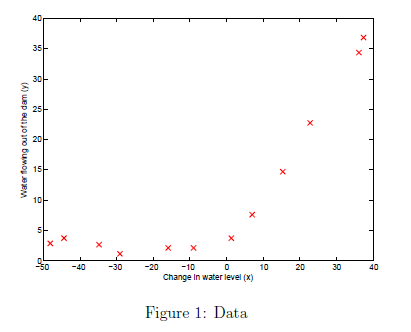

% Load from ex5data1: 
% You will have X, y, Xval, yval, Xtest, ytest in your environment
load ('ex5data1.mat');
% m = Number of examples
m = size(X, 1);

% Plot training data
figure;
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');

### 1.2 Regularized linear regression cost function

Recall that regularized linear regression has the following cost function:


$$J\left(\theta \right)=\frac{1}{2m}\left(\sum_{i=1}^m {\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)}^2 \right)+\frac{\;\lambda }{2m}\left(\sum_{j=1}^n \theta_j^2 \right)$$


where $\lambda$ is a regularization parameter which controls the degree of regularization (thus, helps preventing overfitting). The regularization term puts a penalty on the overall cost $J$. As the magnitudes of the model parameters $\theta_j$ increase, the penalty increases as well. Note that you should not regularize the $\theta_0$ term. (In MATLAB, the $\theta_0$ term is represented as `theta(1)` since indexing in MATLAB starts from 1).

    You should now complete the code in the file `linearRegCostFunction.m`. Your task is to write a function to calculate the regularized linear regression cost function. If possible, try to vectorize your code and avoid writing loops. When you are finished, the code below will run your cost function using `theta` initialized at `[1; 1]`. You should expect to see an output of 303.993.

theta = [1 ; 1];
J = linearRegCostFunction([ones(m, 1) X], y, theta, 1);
fprintf('Cost at theta = [1 ; 1]: %f', J);

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 1.3 Regularized linear regression gradient

Correspondingly, the partial derivative of regularized linear regression's cost for $\theta_j$ is defined as


$$\begin{array}{l}
\frac{\partial J\left(\theta \right)}{\partial \theta_0 }=\frac{\;1}{m}\sum_{i=1}^m \;\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)x^{\left(i\right)} \;\;\textrm{for}\;\;j=0\\
\frac{\partial J\left(\theta \right)}{\partial \theta_j }=\left(\frac{\;1}{m}\sum_{i=1}^m \;\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)x_j^{\left(i\right)} \right)+\frac{\lambda }{m}\theta_j \;\;\;\textrm{for}\;\;j>0
\end{array}$$


In `linearRegCostFunction.m`, add code to calculate the gradient, returning it in the variable `grad`. When you are finished, the code below will run your gradient function using theta initialized at [1; 1]. You should expect to see a gradient of [-15.30; 598.250].

[J, grad] = linearRegCostFunction([ones(m, 1) X], y, theta, 1);
fprintf('Gradient at theta = [1 ; 1]:  [%f; %f] \n',grad(1), grad(2));

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 1.4 Fitting linear regression

Once your cost function and gradient are working correctly, the code in this section will run the code in `trainLinearReg.m` to compute the optimal values of $\theta$. This training function uses `fmincg` to optimize the cost function. In this part, we set regularization parameter $\lambda$ to zero. Because our current implementation of linear regression is trying to fit a 2-dimensional $\theta$, regularization will not be incredibly helpful for a $\theta$ of such low dimension. In the later parts of the exercise, you will be using polynomial regression with regularization.

%  Train linear regression with lambda = 0
lambda = 0;
[theta] = trainLinearReg([ones(m, 1) X], y, lambda);

    Finally, the code below should also plot the best fit line, resulting in an image similar to Figure 2. The best fit line tells us that the model is not a good fit to the data because the data has a nonlinear pattern. 

%  Plot fit over the data
figure;
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');
hold on;
plot(X, [ones(m, 1) X]*theta, '--', 'LineWidth', 2)
hold off;

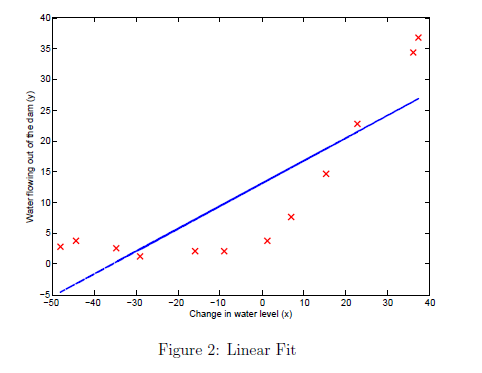

While visualizing the best fit as shown is one possible way to debug your learning algorithm, it is not always easy to visualize the data and model. In the next section, you will implement a function to generate learning curves that can help you debug your learning algorithm even if it is not easy to visualize the data.

## 2. Bias-variance

An important concept in machine learning is the bias-variance tradeoff. Models with high bias are not complex enough for the data and tend to underfit, while models with high variance overfit the training data. In this part of the exercise, you will plot training and test errors on a learning curve to diagnose bias-variance problems.

### 2.1 Learning curves

You will now implement code to generate the learning curves that will be useful in debugging learning algorithms. Recall that a learning curve plots training and cross validation error as a function of training set size. Your job is to fill in `learningCurve.m` so that it returns a vector of errors for the training set and cross validation set.

    To plot the learning curve, we need a training and cross validation set error for different training set sizes. To obtain different training set sizes, you should use different subsets of the original training set `X`. Specically, for a training set size of `i`, you should use the first `i` examples (i.e., `X(1:i,:) `and `y(1:i))`. You can use the `trainLinearReg` function to find the $\theta$ parameters. Note that `lambda` is passed as a parameter to the `learningCurve` function. After learning the $\theta$ parameters, you should compute the error on the training and cross validation sets. Recall that the training error for a dataset is defined as


$$J_{\textrm{train}} \left(\theta \right)=\frac{1}{2m}\left\lbrack \sum_{i=1}^m {\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)}^2 \right\rbrack$$


    In particular, note that the training error does not include the regularization term. One way to compute the training error is to use your existing cost function and set $\lambda$ to 0 only when using it to compute the training error and cross validation error. When you are computing the training set error, make sure you compute it on the training subset (i.e., `X(1:n,:)` and `y(1:n)`, instead of the entire training set). However, for the cross validation error, you should compute it over the entire cross validation set. You should store the computed errors in the vectors `error_train` and `error_val`.  

    In Figure 3, you can observe that both the train error and cross validation error are high when the number of training examples is increased. This reflects a high bias problem in the model - the linear regression model is too simple and is unable to fit our dataset well. In the next section, you will implement polynomial regression to fit a better model for this dataset.

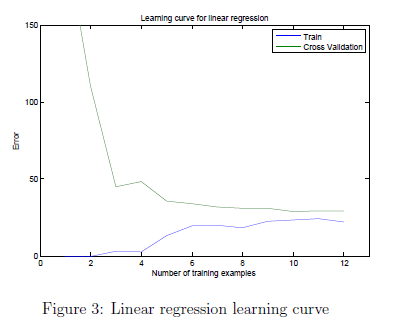

    When you are finished, run the code below to compute the learning curves and produce a plot similar to Figure 3.

lambda = 0;
[error_train, error_val] = learningCurve([ones(m, 1) X], y, [ones(size(Xval, 1), 1) Xval], yval, lambda);

plot(1:m, error_train, 1:m, error_val);
title('Learning curve for linear regression')
legend('Train', 'Cross Validation')
xlabel('Number of training examples')
ylabel('Error')
axis([0 13 0 150])

fprintf('# Training Examples\tTrain Error\tCross Validation Error\n');
for i = 1:m
    fprintf('  \t%d\t\t%f\t%f\n', i, error_train(i), error_val(i));
end

## 3. Polynomial regression

The problem with our linear model was that it was too simple for the data and resulted in underfitting (high bias). In this part of the exercise, you will address this problem by adding more features. For use polynomial regression, our hypothesis has the form:


$$h_\theta(x) =\theta_0+\theta_1\ast (waterLevel)+\theta_2*
(waterLevel)^2+\cdots+\theta_p\ast (waterLevel)^p \\
\qquad\;=\theta_0+\theta_1 x_1+\theta_2 x_2+\cdots+\theta_p x_p \end{aligned}$$


Notice that by defining $x_1 = (\text{waterLevel}), x_2 = (\text{waterLevel)}^2,\ldots,x_p = (\text{waterLevel})^p$, we obtain a linear regression model where the features are the various powers of the original value (*waterLevel*).

    Now, you will add more features using the higher powers of the existing feature $x$ in the dataset. Your task in this part is to complete the code in `polyFeatures.`m so that the function maps the original training set `X` of size $m\times 1$into its higher powers. Specifically, when a training set $X$ of size $m\times 1$ is passed into the function, the function should return a $m\times p$ matrix `X_poly`, where column 1 holds the original values of `X`, column 2 holds the values of `X.^2`, column 3 holds the values of `X.^3`, and so on. Note that you don't have to account for the zero-th power in this function. Now that you have a function that will map features to a higher dimension, the code in the next section will apply it to the training set, the test set, and the cross validation set (which you haven't used yet).

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 3.1 Learning Polynomial Regression

After you have completed `polyFeatures.m`, run the code below to train polynomial regression using your linear regression cost function. Keep in mind that even though we have polynomial terms in our feature vector, we are still solving a linear regression optimization problem. The polynomial terms have simply turned into features that we can use for linear regression. We are using the same cost function and gradient that you wrote for the earlier part of this exercise.

    For this part of the exercise, you will be using a polynomial of degree 8. It turns out that if we run the training directly on the projected data, it will not work well as the features would be badly scaled (e.g., an example with $x = 40$ will now have a feature $x_8 = 40^8 = 6:5\times 10^{12$) Therefore, you will need to use feature normalization. Before learning the parameters $\theta$ for the polynomial regression, code in below will first call `featureNormalize` to normalize the features of the training set, storing the `mu`, `sigma` parameters separately. We have already implemented this function for you and it is the same function from the first exercise.

p = 8;

% Map X onto Polynomial Features and Normalize
X_poly = polyFeatures(X, p);
[X_poly, mu, sigma] = featureNormalize(X_poly);  % Normalize
X_poly = [ones(m, 1), X_poly];                   % Add Ones

% Map X_poly_test and normalize (using mu and sigma)
X_poly_test = polyFeatures(Xtest, p);
X_poly_test = X_poly_test-mu; % uses implicit expansion instead of bsxfun
X_poly_test = X_poly_test./sigma; % uses implicit expansion instead of bsxfun
X_poly_test = [ones(size(X_poly_test, 1), 1), X_poly_test];         % Add Ones

% Map X_poly_val and normalize (using mu and sigma)
X_poly_val = polyFeatures(Xval, p);
X_poly_val = X_poly_val-mu; % uses implicit expansion instead of bsxfun
X_poly_val = X_poly_val./sigma; % uses implicit expansion instead of bsxfun
X_poly_val = [ones(size(X_poly_val, 1), 1), X_poly_val];           % Add Ones

fprintf('Normalized Training Example 1:\n');
fprintf('  %f  \n', X_poly(1, :));

% Train the model
lambda = 0;
[theta] = trainLinearReg(X_poly, y, lambda);

After learning the parameters $\theta$, the code below will generate two plots (Figures 4,5) for polynomial regression with $\lambda = 0$. 

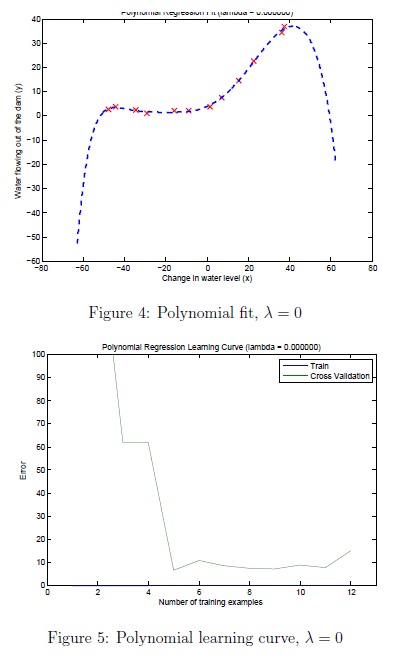

From Figure 4, you should see that the polynomial fit is able to follow the datapoints very well - thus, obtaining a low training error. However, the polynomial fit is very complex and even drops off at the extremes. This is an indicator that the polynomial regression model is overfitting the training data and will not generalize well.

% Plot training data and fit
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
plotFit(min(X), max(X), mu, sigma, theta, p);
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');
title (sprintf('Polynomial Regression Fit (lambda = %f)', lambda));
[error_train, error_val] = learningCurve(X_poly, y, X_poly_val, yval, lambda);
plot(1:m, error_train, 1:m, error_val);
title(sprintf('Polynomial Regression Learning Curve (lambda = %f)', lambda));
xlabel('Number of training examples')
ylabel('Error')
axis([0 13 0 100])
legend('Train', 'Cross Validation')

    To better understand the problems with the unregularized $\lambda=0$ model, you can see that the learning curve (Figure 5) shows the same effect where the low training error is low, but the cross validation error is high. There is a gap between the training and cross validation errors, indicating a high variance problem. One way to combat the overfitting (high-variance) problem is to add regularization to the model. In the next section, you will get to try different $\lambda$ parameters to see how regularization can lead to a better model.

### 3.2 Optional (ungraded) exercise: Adjusting the regularization parameter

In this section, you will get to observe how the regularization parameter affects the bias-variance of regularized polynomial regression. You should now modify the the `lambda` parameter in the code below and try $\lambda = 1,\; 100$. 

% Choose the value of lambda
lambda = 1;
[theta] = trainLinearReg(X_poly, y, lambda);

sqrErrors = 	1.0e+03 *

    0.0046
    0.0014
    1.1805
    1.3570
    0.0079
    0.0045
    0.2164
    0.0068
    0.0140
    0.0139


sqrErrors = 	1.0e+03 *

    0.0044
    0.0013
    1.1720
    1.3473
    0.0087
    0.0043
    0.2144
    0.0069
    0.0136
    0.0146


sqrErrors = 	1.0e+03 *

    0.0041
    0.0013
    1.1549
    1.3280
    0.0106
    0.0040
    0.2106
    0.0070
    0.0129
    0.0160


sqrErrors = 	1.0e+03 *

    0.0033
    0.0011
    1.1046
    1.2710
    0.0171
    0.0030
    0.1991
    0.0073
    0.0108
    0.0206


sqrErrors = 	1.0e+03 *

    0.0014
    0.0007
    0.9602
    1.1074
    0.0461
    0.0010
    0.1667
    0.0082
    0.0056
    0.0378


sqrErrors =     0.5131
    0.0492
  587.7331
  684.2159
  217.3776
    1.6593
   86.7847
   11.3282
    0.1598
  120.7176


Iteration     1 | Cost: 8.320954e+01


sqrErrors =     0.2326
    0.0050
  188.2007
  207.6136
    1.3117
    0.0023
   66.8271
    1.5438
    0.1143
    1.0991


Iteration     2 | Cost: 2.907694e+01


sqrErrors =    45.4365
    7.2797
   75.9863
   83.2204
  778.7647
   73.8207
   22.6233
    7.6863
   97.5437
  344.2149


sqrErrors =     3.3587
    0.8331
   42.6149
   47.1560
   66.6795
    7.7639
   16.2437
    3.0028
    8.6179
   44.3371


Iteration     3 | Cost: 1.613078e+01


sqrErrors =     2.5176
    2.7749
   13.6197
   19.1304
   16.7852
    6.7421
    3.6347
    0.1239
   10.8616
    1.4323


sqrErrors =     2.8043
    1.9508
    0.0015
    0.1274
    0.0812
    7.0990
    7.1046
    0.1545
   10.0300
    2.5930


Iteration     4 | Cost: 7.814702e+00


sqrErrors = 	1.0e+03 *

    0.1057
    0.0000
    2.4999
    2.8784
    5.6760
    0.1404
    0.6195
    0.0729
    0.2002
    2.1463


sqrErrors =     0.2296
    1.6075
   24.6498
   25.4402
   52.9607
    1.4714
   23.8912
    0.2501
    2.0604
   10.1353


sqrErrors =     2.3312
    1.9065
    0.3360
    0.0965
    0.4224
    6.1750
    8.6448
    0.0799
    8.7199
    1.0355


Iteration     5 | Cost: 7.711843e+00


sqrErrors =     3.3373
    2.5883
    1.2125
    0.9922
    0.0873
    7.9509
    6.5772
    0.0117
   11.1094
    1.2509


Iteration     6 | Cost: 7.588232e+00


sqrErrors =     2.5362
    2.2714
    1.1244
    1.0636
    2.0060
    6.8255
    5.9703
    0.0009
   10.4722
    0.1599


Iteration     7 | Cost: 7.481019e+00


sqrErrors =     2.2982
    1.9364
    0.4088
    0.4954
    1.2939
    6.8301
    3.8600
    0.0169
   11.6396
    0.3018


Iteration     8 | Cost: 7.347791e+00


sqrErrors =     3.1386
    1.7321
    0.5906
    0.5836
    8.8186
    8.1242
    4.4785
    0.4584
   12.3869
    9.8405


sqrErrors =     2.3764
    1.9154
    0.4255
    0.5039
    0.5282
    6.9545
    3.9198
    0.0341
   11.7133
    0.6530


Iteration     9 | Cost: 7.337625e+00


sqrErrors =     1.9972
    1.7028
    0.5453
    0.6362
    0.5602
    6.2371
    4.4204
    0.0538
   10.7633
    0.6372


Iteration    10 | Cost: 7.322456e+00


sqrErrors =     1.9460
    1.6354
    0.4706
    0.5739
    0.0586
    6.1588
    4.2538
    0.0838
   10.7587
    1.1812


sqrErrors =     1.9631
    1.6579
    0.4951
    0.5945
    0.1701
    6.1851
    4.3095
    0.0729
   10.7602
    0.9796


Iteration    11 | Cost: 7.315629e+00


sqrErrors =     1.7337
    1.5769
    0.5412
    0.6618
    0.1447
    5.7234
    4.5316
    0.0745
   10.1827
    0.9642


sqrErrors =     1.3177
    1.4209
    0.6397
    0.8072
    0.1001
    4.8537
    4.9925
    0.0775
    9.0754
    0.9337


Iteration    12 | Cost: 7.294252e+00


sqrErrors =     1.3736
    1.8682
    0.7110
    0.9533
    1.2072
    4.8348
    4.8203
    0.0003
    9.0441
    0.1219


sqrErrors =     1.3408
    1.5994
    0.6689
    0.8665
    0.4116
    4.8459
    4.9205
    0.0244
    9.0624
    0.5037


Iteration    13 | Cost: 7.285740e+00


sqrErrors =     1.6104
    1.9080
    0.5359
    0.7516
    0.2911
    5.3531
    4.2744
    0.0022
    9.8243
    0.4938


Iteration    14 | Cost: 7.275663e+00


sqrErrors =     1.3011
    1.1029
    0.3853
    0.5662
    0.7676
    5.0298
    4.0969
    0.2944
    9.7456
    3.0669


sqrErrors =     1.5780
    1.8176
    0.5197
    0.7318
    0.1584
    5.3203
    4.2565
    0.0094
    9.8164
    0.6522


sqrErrors =     1.5918
    1.8559
    0.5266
    0.7402
    0.2100
    5.3343
    4.2642
    0.0057
    9.8198
    0.5820


Iteration    15 | Cost: 7.275175e+00


sqrErrors =     1.5340
    1.8029
    0.5420
    0.7621
    0.2323
    5.2329
    4.3087
    0.0080
    9.7052
    0.5697


sqrErrors =     1.4217
    1.6993
    0.5735
    0.8068
    0.2802
    5.0331
    4.3984
    0.0139
    9.4782
    0.5455


Iteration    16 | Cost: 7.273614e+00


sqrErrors =     1.3653
    1.6027
    0.5574
    0.8072
    0.1702
    4.9653
    4.2786
    0.0268
    9.4880
    0.6762


Iteration    17 | Cost: 7.272064e+00


sqrErrors =     1.3209
    1.5807
    0.5750
    0.8587
    0.2187
    4.8985
    4.1579
    0.0253
    9.4878
    0.6116


Iteration    18 | Cost: 7.269894e+00


sqrErrors =     1.5460
    1.8413
    0.5162
    0.8002
    0.1852
    5.3026
    3.8394
    0.0044
   10.0154
    0.5704


sqrErrors =     1.4362
    1.7141
    0.5439
    0.8279
    0.2009
    5.1073
    3.9901
    0.0123
    9.7613
    0.5899


Iteration    19 | Cost: 7.269129e+00


sqrErrors =     1.4334
    1.8261
    0.5840
    0.8836
    0.4546
    5.0520
    4.0681
    0.0013
    9.6374
    0.3574


sqrErrors =     1.4356
    1.7360
    0.5517
    0.8388
    0.2430
    5.0963
    4.0055
    0.0092
    9.7367
    0.5393


Iteration    20 | Cost: 7.268978e+00


sqrErrors =     1.4281
    1.7526
    0.5444
    0.8330
    0.2335
    5.0709
    4.0039
    0.0074
    9.7018
    0.5338


sqrErrors =     1.4130
    1.7860
    0.5298
    0.8216
    0.2151
    5.0201
    4.0006
    0.0044
    9.6321
    0.5227


Iteration    21 | Cost: 7.268390e+00


sqrErrors =     1.2213
    1.6161
    0.6812
    1.0331
    0.3056
    4.6517
    4.2434
    0.0121
    9.1618
    0.4737


sqrErrors =     1.3837
    1.7602
    0.5511
    0.8515
    0.2275
    4.9645
    4.0362
    0.0053
    9.5616
    0.5153


Iteration    22 | Cost: 7.268323e+00


sqrErrors =     1.3697
    1.7359
    0.5607
    0.8685
    0.1992
    4.9446
    4.0274
    0.0071
    9.5502
    0.5478


Iteration    23 | Cost: 7.268274e+00


sqrErrors =     1.3379
    1.7019
    0.5735
    0.8973
    0.2028
    4.8944
    3.9964
    0.0089
    9.5206
    0.5495


sqrErrors =     1.3510
    1.7159
    0.5682
    0.8854
    0.2013
    4.9151
    4.0092
    0.0082
    9.5328
    0.5488


Iteration    24 | Cost: 7.268234e+00


sqrErrors =     1.3575
    1.7283
    0.5599
    0.8753
    0.2163
    4.9261
    3.9940
    0.0070
    9.5491
    0.5306


Iteration    25 | Cost: 7.268181e+00


sqrErrors =     1.3841
    1.7494
    0.5373
    0.8473
    0.1922
    4.9797
    3.9378
    0.0064
    9.6286
    0.5500


sqrErrors =     1.3676
    1.7363
    0.5513
    0.8646
    0.2070
    4.9465
    3.9726
    0.0068
    9.5793
    0.5379


Iteration    26 | Cost: 7.268166e+00


sqrErrors =     1.3778
    1.7533
    0.5410
    0.8516
    0.2181
    4.9634
    3.9546
    0.0056
    9.6018
    0.5222


sqrErrors =     1.3739
    1.7468
    0.5449
    0.8565
    0.2139
    4.9570
    3.9614
    0.0060
    9.5932
    0.5282


Iteration    27 | Cost: 7.268157e+00


sqrErrors = 12×1
    1.3493
    1.7374
    0.5652
    0.8828
    0.2396
    4.9016
    4.0156
    0.0058
    9.5077
    0.5034


sqrErrors = 12×1
    1.3714
    1.7459
    0.5469
    0.8591
    0.2164
    4.9514
    3.9668
    0.0060
    9.5847
    0.5257


Iteration    28 | Cost: 7.268156e+00


sqrErrors = 12×1
    1.3700
    1.7455
    0.5481
    0.8609
    0.2148
    4.9479
    3.9697
    0.0060
    9.5791
    0.5268


sqrErrors = 12×1
    1.3682
    1.7451
    0.5498
    0.8633
    0.2128
    4.9434
    3.9735
    0.0060
    9.5719
    0.5282


Iteration    29 | Cost: 7.268154e+00


sqrErrors = 12×1
    1.3726
    1.7495
    0.5453
    0.8581
    0.2073
    4.9515
    3.9635
    0.0058
    9.5838
    0.5323


sqrErrors = 12×1
    1.3705
    1.7474
    0.5475
    0.8606
    0.2099
    4.9476
    3.9683
    0.0059
    9.5781
    0.5303


Iteration    30 | Cost: 7.268153e+00


sqrErrors = 12×1
    1.3713
    1.7499
    0.5459
    0.8588
    0.2116
    4.9484
    3.9663
    0.0057
    9.5790
    0.5278


sqrErrors = 12×1
    1.3722
    1.7524
    0.5444
    0.8570
    0.2133
    4.9492
    3.9643
    0.0055
    9.5799
    0.5253


Iteration    31 | Cost: 7.268150e+00


sqrErrors = 12×1
    1.3662
    1.7498
    0.5499
    0.8654
    0.2160
    4.9357
    3.9727
    0.0056
    9.5606
    0.5227


sqrErrors = 12×1
    1.3693
    1.7511
    0.5470
    0.8610
    0.2146
    4.9428
    3.9683
    0.0055
    9.5707
    0.5240


Iteration    32 | Cost: 7.268149e+00


sqrErrors = 12×1
    1.3688
    1.7504
    0.5478
    0.8628
    0.2103
    4.9416
    3.9666
    0.0056
    9.5697
    0.5282


sqrErrors = 12×1
    1.3689
    1.7506
    0.5475
    0.8622
    0.2118
    4.9420
    3.9672
    0.0056
    9.5700
    0.5268


Iteration    33 | Cost: 7.268149e+00


sqrErrors = 12×1
    1.3702
    1.7518
    0.5436
    0.8576
    0.2124
    4.9446
    3.9600
    0.0056
    9.5755
    0.5262


sqrErrors = 12×1
    1.3696
    1.7512
    0.5455
    0.8598
    0.2121
    4.9433
    3.9634
    0.0056
    9.5729
    0.5265


Iteration    34 | Cost: 7.268148e+00


sqrErrors = 12×1
    1.3674
    1.7509
    0.5466
    0.8614
    0.2192
    4.9384
    3.9665
    0.0055
    9.5659
    0.5199


sqrErrors = 12×1
    1.3694
    1.7512
    0.5456
    0.8599
    0.2128
    4.9429
    3.9637
    0.0056
    9.5722
    0.5258


Iteration    35 | Cost: 7.268148e+00


sqrErrors = 12×1
    1.3694
    1.7510
    0.5462
    0.8609
    0.2127
    4.9429
    3.9638
    0.0056
    9.5723
    0.5260


Iteration    36 | Cost: 7.268148e+00


sqrErrors = 12×1
    1.3700
    1.7507
    0.5454
    0.8599
    0.2107
    4.9444
    3.9618
    0.0057
    9.5747
    0.5283


sqrErrors = 12×1
    1.3694
    1.7510
    0.5462
    0.8608
    0.2125
    4.9430
    3.9636
    0.0056
    9.5725
    0.5263


Iteration    37 | Cost: 7.268148e+00


sqrErrors = 12×1
    1.3694
    1.7509
    0.5461
    0.8607
    0.2125
    4.9430
    3.9636
    0.0056
    9.5724
    0.5263


sqrErrors = 12×1
    1.3693
    1.7506
    0.5460
    0.8606
    0.2126
    4.9428
    3.9636
    0.0056
    9.5722
    0.5264


Iteration    38 | Cost: 7.268148e+00


sqrErrors = 12×1
    1.3691
    1.7507
    0.5463
    0.8610
    0.2132
    4.9423
    3.9641
    0.0056
    9.5714
    0.5258


sqrErrors = 12×1
    1.3692
    1.7506
    0.5461
    0.8607
    0.2128
    4.9426
    3.9638
    0.0056
    9.5720
    0.5262


Iteration    39 | Cost: 7.268148e+00


sqrErrors = 12×1
    1.3693
    1.7508
    0.5462
    0.8608
    0.2128
    4.9428
    3.9637
    0.0056
    9.5722
    0.5262


sqrErrors = 12×1
    1.3696
    1.7510
    0.5463
    0.8611
    0.2128
    4.9433
    3.9634
    0.0056
    9.5727
    0.5262


Iteration    40 | Cost: 7.268148e+00


sqrErrors = 12×1
    1.3698
    1.7510
    0.5460
    0.8608
    0.2122
    4.9438
    3.9629
    0.0056
    9.5734
    0.5268


sqrErrors = 12×1
    1.3697
    1.7510
    0.5462
    0.8610
    0.2126
    4.9434
    3.9633
    0.0056
    9.5729
    0.5263


Iteration    41 | Cost: 7.268148e+00


sqrErrors = 12×1
    1.3696
    1.7509
    0.5462
    0.8609
    0.2127
    4.9432
    3.9634
    0.0056
    9.5726
    0.5264


sqrErrors = 12×1
    1.3694
    1.7508
    0.5461
    0.8607
    0.2127
    4.9429
    3.9636
    0.0056
    9.5721
    0.5264


Iteration    42 | Cost: 7.268148e+00


sqrErrors = 12×1
    1.3693
    1.7512
    0.5469
    0.8619
    0.2140
    4.9424
    3.9647
    0.0056
    9.5709
    0.5251


sqrErrors = 12×1
    1.3694
    1.7508
    0.5461
    0.8608
    0.2128
    4.9428
    3.9637
    0.0056
    9.5720
    0.5263


sqrErrors = 12×1
    1.3694
    1.7508
    0.5461
    0.8608
    0.2128
    4.9429
    3.9637
    0.0056
    9.5720
    0.5263


Iteration    43 | Cost: 7.268148e+00


sqrErrors = 12×1
    1.3695
    1.7508
    0.5461
    0.8608
    0.2128
    4.9430
    3.9636
    0.0056
    9.5721
    0.5263


Iteration    44 | Cost: 7.268148e+00


sqrErrors = 12×1
    1.3695
    1.7508
    0.5460
    0.8607
    0.2126
    4.9431
    3.9635
    0.0056
    9.5723
    0.5265


sqrErrors = 12×1
    1.3695
    1.7508
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5722
    0.5264


Iteration    45 | Cost: 7.268148e+00


sqrErrors = 12×1
    1.3695
    1.7508
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5721
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5721
    0.5263


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2128
    4.9430
    3.9637
    0.0056
    9.5721
    0.5263


Iteration    46 | Cost: 7.268148e+00


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9431
    3.9636
    0.0056
    9.5722
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5721
    0.5264


Iteration    47 | Cost: 7.268148e+00


sqrErrors = 12×1
    1.3696
    1.7510
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5721
    0.5264


Iteration    48 | Cost: 7.268148e+00


sqrErrors = 12×1
    1.3695
    1.7510
    0.5461
    0.8608
    0.2127
    4.9430
    3.9637
    0.0056
    9.5719
    0.5264


sqrErrors = 12×1
    1.3695
    1.7510
    0.5461
    0.8608
    0.2127
    4.9430
    3.9637
    0.0056
    9.5720
    0.5264


Iteration    49 | Cost: 7.268148e+00


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2128
    4.9429
    3.9637
    0.0056
    9.5720
    0.5263


sqrErrors = 12×1
    1.3695
    1.7510
    0.5461
    0.8608
    0.2127
    4.9430
    3.9637
    0.0056
    9.5720
    0.5264


Iteration    50 | Cost: 7.268148e+00


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5721
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9637
    0.0056
    9.5720
    0.5264


Iteration    51 | Cost: 7.268148e+00


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2128
    4.9430
    3.9637
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9637
    0.0056
    9.5720
    0.5264


Iteration    52 | Cost: 7.268148e+00


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


Iteration    53 | Cost: 7.268148e+00


sqrErrors = 12×1
    1.3695
    1.7508
    0.5461
    0.8609
    0.2128
    4.9430
    3.9636
    0.0056
    9.5721
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


Iteration    54 | Cost: 7.268148e+00


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


Iteration    55 | Cost: 7.268148e+00


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2128
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


Iteration    56 | Cost: 7.268148e+00


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5721
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5721
    0.5264


Iteration    57 | Cost: 7.268148e+00


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


Iteration    58 | Cost: 7.268148e+00


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2128
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


Iteration    59 | Cost: 7.268148e+00


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9637
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


Iteration    60 | Cost: 7.268148e+00


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


Iteration    61 | Cost: 7.268148e+00


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


Iteration    62 | Cost: 7.268148e+00


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2128
    4.9430
    3.9637
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


Iteration    63 | Cost: 7.268148e+00


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


Iteration    64 | Cost: 7.268148e+00


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


Iteration    65 | Cost: 7.268148e+00


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


Iteration    66 | Cost: 7.268148e+00


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


Iteration    67 | Cost: 7.268148e+00


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


Iteration    68 | Cost: 7.268148e+00


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


Iteration    69 | Cost: 7.268148e+00


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


Iteration    70 | Cost: 7.268148e+00


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


Iteration    71 | Cost: 7.268148e+00


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


Iteration    72 | Cost: 7.268148e+00


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


Iteration    73 | Cost: 7.268148e+00


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


Iteration    74 | Cost: 7.268148e+00


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


Iteration    75 | Cost: 7.268148e+00


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


Iteration    77 | Cost: 7.268148e+00


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


Iteration    78 | Cost: 7.268148e+00


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


Iteration    80 | Cost: 7.268148e+00


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


sqrErrors = 12×1
    1.3695
    1.7509
    0.5461
    0.8608
    0.2127
    4.9430
    3.9636
    0.0056
    9.5720
    0.5264


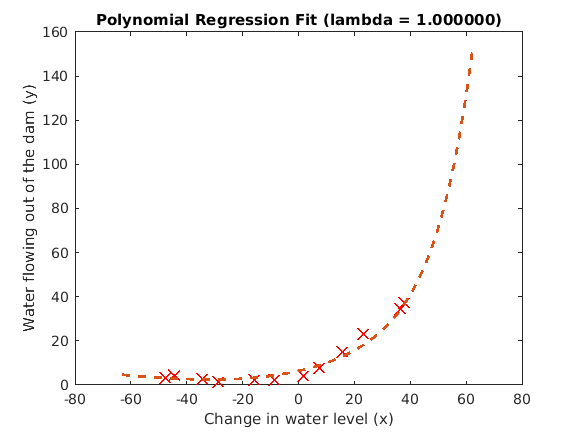


% Plot training data and fit
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
plotFit(min(X), max(X), mu, sigma, theta, p);
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');
title (sprintf('Polynomial Regression Fit (lambda = %f)', lambda));

[error_train, error_val] = learningCurve(X_poly, y, X_poly_val, yval, lambda);

sqrErrors = 4.5553

sqrErrors = 2.8805

sqrErrors = 0.6773

Iteration     1 | Cost: 5.280051e-01


sqrErrors = 7.1557

sqrErrors = 5.7422e-04

Iteration     2 | Cost: 2.083531e-01


sqrErrors = 0.8479

sqrErrors = 0.1111

Iteration     3 | Cost: 9.810873e-02


sqrErrors = 0.0017

Iteration     4 | Cost: 1.501116e-03


sqrErrors = 53.2731

sqrErrors = 0.4799

sqrErrors = 0.0010

sqrErrors = 1.9094e-04

Iteration     5 | Cost: 1.089480e-03


sqrErrors = 7.3913e-05

sqrErrors = 1.9722e-31

Iteration     6 | Cost: 4.451497e-31


sqrErrors = 1.1077e-26

sqrErrors = 9.5452e-29

sqrErrors = 1.9722e-31

sqrErrors = 1.9722e-31

Iteration     7 | Cost: 3.829364e-31


sqrErrors = 1.9722e-31

sqrErrors = 1.9722e-31

Iteration     8 | Cost: 1.258474e-31


sqrErrors = 0

sqrErrors = 7.8886e-31

sqrErrors = 1.9722e-31

sqrErrors = 1.9722e-31

Iteration     9 | Cost: 1.098718e-31


sqrErrors = 1.9722e-31

sqrErrors = 1.9722e-31

sqrErrors = 1.9722e-31

sqrErrors = 1.9722e-31

sqrErrors = 1.9722e-31

sqrErrors = 1.9722e-31

sqrErrors = 1.9722e-31

sqrErrors = 1.9722e-31

sqrErrors = 1.9722e-31

sqrErrors = 1.9722e-31

sqrErrors = 1.9722e-31

sqrErrors = 1.9722e-31

sqrErrors = 1.9722e-31

sqrErrors = 1.9722e-31

sqrErrors = 1.9722e-31

sqrErrors = 1.9722e-31

sqrErrors = 1.9722e-31

sqrErrors = 1.9722e-31

sqrErrors = 1.9722e-31

sqrErrors = 1.9722e-31

sqrErrors = 1.9722e-31

sqrErrors = 1.9722e-31

sqrErrors = 1.9722e-31

sqrErrors = 1.9722e-31

sqrErrors = 1.9722e-31

sqrErrors = 1.9722e-31

sqrErrors = 1.9722e-31

sqrErrors = 1.9722e-31

sqrErrors = 1.9722e-31

sqrErrors = 1.9722e-31

sqrErrors = 1.9722e-31

sqrErrors = 1.9722e-31

sqrErrors = 1.9722e-31

sqrErrors = 1.9722e-31

sqrErrors = 1.9722e-31

sqrErrors = 1.9722e-31

sqrErrors = 1.9722e-31

sqrErrors = 1.9722e-31

sqrErrors = 1.9722e-31

sqrErrors = 1.9722e-31

sqrErrors = 1.9722e-31

sqrErrors = 1.9722e-31

sqrErrors = 1.9722e-31

sqrErrors = 21×1
    4.1449
    3.7363
  884.3937
   72.0690
  882.1916
    7.9810
    5.3698
  405.7005
    4.5555
  337.4382


sqrErrors = 2×1
    4.5553
    1.3765


sqrErrors = 2×1
    2.4489
    0.5202


sqrErrors = 2×1
    0.2159
    0.0232


Iteration     1 | Cost: 2.032751e-01


sqrErrors = 2×1
    3.4355
    0.1761


sqrErrors = 2×1
    0.0542
    0.0090


Iteration     2 | Cost: 1.041953e-01


sqrErrors = 2×1
    0.1472
    0.6584


sqrErrors = 2×1
    0.0761
    0.0897


Iteration     3 | Cost: 7.367762e-02


sqrErrors = 2×1
    2.4788
    0.0045


sqrErrors = 2×1
    0.1646
    0.0763


sqrErrors = 2×1
    0.0982
    0.0857


Iteration     4 | Cost: 7.279642e-02


sqrErrors = 2×1
    0.0488
    0.1595


sqrErrors = 2×1
    0.0918
    0.0928


Iteration     5 | Cost: 7.269797e-02


sqrErrors = 2×1
    0.0709
    0.0725


sqrErrors = 2×1
    0.0896
    0.0907


sqrErrors = 2×1
    0.0910
    0.0920


Iteration     6 | Cost: 7.269533e-02


sqrErrors = 2×1
    0.0950
    0.0880


sqrErrors = 2×1
    0.0914
    0.0915


Iteration     7 | Cost: 7.269502e-02


sqrErrors = 2×1
    0.0915
    0.0916


sqrErrors = 2×1
    0.0916
    0.0916


Iteration     8 | Cost: 7.269437e-02


sqrErrors = 2×1
    0.0852
    0.0921


sqrErrors = 2×1
    0.0910
    0.0916


sqrErrors = 2×1
    0.0915
    0.0916


Iteration     9 | Cost: 7.269436e-02


sqrErrors = 2×1
    0.0916
    0.0915


sqrErrors = 2×1
    0.0915
    0.0915


Iteration    10 | Cost: 7.269436e-02


sqrErrors = 2×1
    0.0917
    0.0915


sqrErrors = 2×1
    0.0915
    0.0915


Iteration    11 | Cost: 7.269436e-02


sqrErrors = 2×1
    0.0915
    0.0916


sqrErrors = 2×1
    0.0915
    0.0915


Iteration    12 | Cost: 7.269436e-02


sqrErrors = 2×1
    0.0915
    0.0915


sqrErrors = 2×1
    0.0915
    0.0915


Iteration    13 | Cost: 7.269436e-02


sqrErrors = 2×1
    0.0916
    0.0915


sqrErrors = 2×1
    0.0916
    0.0915


sqrErrors = 2×1
    0.0915
    0.0915


sqrErrors = 2×1
    0.0915
    0.0915


Iteration    14 | Cost: 7.269436e-02


sqrErrors = 2×1
    0.0915
    0.0915


Iteration    15 | Cost: 7.269436e-02


sqrErrors = 2×1
    0.0915
    0.0915


sqrErrors = 2×1
    0.0915
    0.0915


Iteration    16 | Cost: 7.269436e-02


sqrErrors = 2×1
    0.0915
    0.0915


sqrErrors = 2×1
    0.0915
    0.0915


Iteration    17 | Cost: 7.269436e-02


sqrErrors = 2×1
    0.0915
    0.0915


sqrErrors = 2×1
    0.0915
    0.0915


Iteration    18 | Cost: 7.269436e-02


sqrErrors = 2×1
    0.0915
    0.0915


sqrErrors = 2×1
    0.0915
    0.0915


sqrErrors = 2×1
    0.0915
    0.0915


Iteration    19 | Cost: 7.269436e-02


sqrErrors = 2×1
    0.0915
    0.0915


sqrErrors = 2×1
    0.0915
    0.0915


Iteration    20 | Cost: 7.269436e-02


sqrErrors = 2×1
    0.0915
    0.0915


sqrErrors = 2×1
    0.0915
    0.0915


Iteration    21 | Cost: 7.269436e-02


sqrErrors = 2×1
    0.0915
    0.0915


sqrErrors = 2×1
    0.0915
    0.0915


Iteration    22 | Cost: 7.269436e-02


sqrErrors = 2×1
    0.0915
    0.0915


sqrErrors = 2×1
    0.0915
    0.0915


sqrErrors = 2×1
    0.0915
    0.0915


sqrErrors = 2×1
    0.0915
    0.0915


sqrErrors = 2×1
    0.0915
    0.0915


sqrErrors = 2×1
    0.0915
    0.0915


sqrErrors = 2×1
    0.0915
    0.0915


sqrErrors = 2×1
    0.0915
    0.0915


sqrErrors = 2×1
    0.0915
    0.0915


sqrErrors = 2×1
    0.0915
    0.0915


sqrErrors = 2×1
    0.0915
    0.0915


sqrErrors = 2×1
    0.0915
    0.0915


sqrErrors = 2×1
    0.0915
    0.0915


sqrErrors = 2×1
    0.0915
    0.0915


sqrErrors = 2×1
    0.0915
    0.0915


sqrErrors = 2×1
    0.0915
    0.0915


sqrErrors = 2×1
    0.0915
    0.0915


sqrErrors = 2×1
    0.0915
    0.0915


sqrErrors = 2×1
    0.0915
    0.0915


sqrErrors = 2×1
    0.0915
    0.0915


sqrErrors = 2×1
    0.0915
    0.0915


sqrErrors = 2×1
    0.0915
    0.0915


sqrErrors = 2×1
    0.0915
    0.0915


sqrErrors = 2×1
    0.0915
    0.0915


sqrErrors = 2×1
    0.0915
    0.0915


sqrErrors = 2×1
    0.0915
    0.0915


sqrErrors = 2×1
    0.0915
    0.0915


sqrErrors = 2×1
    0.0915
    0.0915


sqrErrors = 2×1
    0.0915
    0.0915


sqrErrors = 2×1
    0.0915
    0.0915


sqrErrors = 2×1
    0.0915
    0.0915


sqrErrors = 2×1
    0.0915
    0.0915


sqrErrors = 2×1
    0.0915
    0.0915


sqrErrors = 2×1
    0.0915
    0.0915


sqrErrors = 2×1
    0.0915
    0.0915


sqrErrors = 2×1
    0.0915
    0.0915


sqrErrors = 2×1
    0.0915
    0.0915


sqrErrors = 2×1
    0.0915
    0.0915


sqrErrors = 2×1
    0.0915
    0.0915


sqrErrors = 2×1
    0.0915
    0.0915


sqrErrors = 2×1
    0.0915
    0.0915


sqrErrors = 2×1
    0.0915
    0.0915


sqrErrors = 2×1
    0.0915
    0.0915


sqrErrors = 21×1
    5.5353
    4.8983
  902.3233
  110.1123
  902.4553
   17.3416
    6.1750
  413.9916
    0.3647
  344.6187


sqrErrors = 3×1
	1.0e+03 *

    0.0046
    0.0014
    1.1805


sqrErrors = 3×1
	1.0e+03 *

    0.0045
    0.0014
    1.1746


sqrErrors = 3×1
	1.0e+03 *

    0.0044
    0.0014
    1.1628


sqrErrors = 3×1
	1.0e+03 *

    0.0040
    0.0014
    1.1278


sqrErrors = 3×1
	1.0e+03 *

    0.0031
    0.0013
    1.0258


sqrErrors = 3×1
    1.0425
    1.1867
  748.9536


sqrErrors = 3×1
    1.4534
    0.8493
  179.1001


Iteration     1 | Cost: 3.958682e+01


sqrErrors = 3×1
	1.0e+03 *

    0.0291
    0.0011
    2.8152


sqrErrors = 3×1
    3.3175
    0.4033
   12.9967


Iteration     2 | Cost: 2.172738e+01


sqrErrors = 3×1
   45.9917
  418.2395
  398.6062


sqrErrors = 3×1
    5.3705
    2.1714
   27.4691


Iteration     3 | Cost: 2.007128e+01


sqrErrors = 3×1
    3.4709
    6.5678
    6.2861


Iteration     4 | Cost: 1.908475e+01


sqrErrors = 3×1
   47.2187
    1.1942
   82.4278


sqrErrors = 3×1
    0.9793
    4.8278
   10.0133


sqrErrors = 3×1
    2.6683
    6.0846
    7.1820


Iteration     5 | Cost: 1.903782e+01


sqrErrors = 3×1
    2.6623
    5.7663
    8.1375


sqrErrors = 3×1
    2.6504
    5.1552
   10.2276


sqrErrors = 3×1
    2.6282
    4.1022
   14.7874


Iteration     6 | Cost: 1.872107e+01


sqrErrors = 3×1
    4.2676
    1.4047
   10.0053


Iteration     7 | Cost: 1.855211e+01


sqrErrors = 3×1
    3.3893
    6.2200
   47.5652


sqrErrors = 3×1
    4.1752
    1.7321
   12.5067


Iteration     8 | Cost: 1.852112e+01


sqrErrors = 3×1
    4.0049
    2.5865
   11.1307


sqrErrors = 3×1
    4.0628
    2.2748
   11.5927


Iteration     9 | Cost: 1.850029e+01


sqrErrors = 3×1
    0.9440
    0.7099
   10.4234


sqrErrors = 3×1
    3.6528
    2.0784
   11.4729


sqrErrors = 3×1
    3.7877
    2.1432
   11.5130


Iteration    10 | Cost: 1.849891e+01


sqrErrors = 3×1
    3.3725
    1.9641
   15.3047


sqrErrors = 3×1
    3.7450
    2.1249
   11.8679


sqrErrors = 3×1
    3.7770
    2.1386
   11.6013


Iteration    11 | Cost: 1.849887e+01


sqrErrors = 3×1
    3.7810
    2.1345
   11.5860


sqrErrors = 3×1
    3.7860
    2.1293
   11.5668


Iteration    12 | Cost: 1.849879e+01


sqrErrors = 3×1
    3.4439
    1.8320
   11.4111


sqrErrors = 3×1
    3.7511
    2.0986
   11.5512


sqrErrors = 3×1
    3.7785
    2.1227
   11.5635


Iteration    13 | Cost: 1.849879e+01


sqrErrors = 3×1
    3.7860
    2.1156
   11.5908


sqrErrors = 3×1
    3.7801
    2.1212
   11.5691


Iteration    14 | Cost: 1.849879e+01


sqrErrors = 3×1
    3.7861
    2.1205
   11.5530


sqrErrors = 3×1
    3.7812
    2.1211
   11.5661


Iteration    15 | Cost: 1.849879e+01


sqrErrors = 3×1
    3.7751
    2.1165
   11.5609


sqrErrors = 3×1
    3.7806
    2.1206
   11.5656


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


Iteration    16 | Cost: 1.849879e+01


sqrErrors = 3×1
    3.7810
    2.1209
   11.5673


sqrErrors = 3×1
    3.7811
    2.1210
   11.5662


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


Iteration    17 | Cost: 1.849879e+01


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


Iteration    18 | Cost: 1.849879e+01


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


Iteration    19 | Cost: 1.849879e+01


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


Iteration    20 | Cost: 1.849879e+01


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


Iteration    21 | Cost: 1.849879e+01


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


Iteration    22 | Cost: 1.849879e+01


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


Iteration    24 | Cost: 1.849879e+01


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


Iteration    25 | Cost: 1.849879e+01


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


Iteration    26 | Cost: 1.849879e+01


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 3×1
    3.7811
    2.1210
   11.5661


sqrErrors = 21×1
    0.0376
    0.0357
   13.8109
   73.5996
    0.3208
    9.7345
    1.9139
   13.0162
    3.3071
    7.9733


sqrErrors = 4×1
	1.0e+03 *

    0.0046
    0.0014
    1.1805
    1.3570


sqrErrors = 4×1
	1.0e+03 *

    0.0045
    0.0014
    1.1769
    1.3528


sqrErrors = 4×1
	1.0e+03 *

    0.0045
    0.0014
    1.1695
    1.3442


sqrErrors = 4×1
	1.0e+03 *

    0.0043
    0.0014
    1.1476
    1.3188


sqrErrors = 4×1
	1.0e+03 *

    0.0039
    0.0014
    1.0830
    1.2439


sqrErrors = 4×1
	1.0e+03 *

    0.0027
    0.0016
    0.9004
    1.0325


sqrErrors = 4×1
    0.4172
    1.9932
  453.8270
  516.1987


sqrErrors = 4×1
    2.3450
    3.1004
    4.8577
    4.2731


Iteration     1 | Cost: 1.883439e+01


sqrErrors = 4×1
	1.0e+03 *

    0.5160
    1.2530
    0.0001
    0.0017


sqrErrors = 4×1
   13.3214
    3.8221
    4.0770
    3.9594


Iteration     2 | Cost: 1.695119e+01


sqrErrors = 4×1
    2.0245
    9.2703
    3.2531
    2.0615


Iteration     3 | Cost: 1.546680e+01


sqrErrors = 4×1
    0.3473
    6.5856
    5.0938
    4.2675


sqrErrors = 4×1
    0.7830
    2.3859
    3.7050
    2.5735


Iteration     4 | Cost: 1.486258e+01


sqrErrors = 4×1
   11.8023
    3.9117
    0.8057
    0.7152


sqrErrors = 4×1
    3.5320
    2.9362
    2.3236
    1.7121


Iteration     5 | Cost: 1.462699e+01


sqrErrors = 4×1
    8.3989
    3.8743
   16.0645
   17.4498


sqrErrors = 4×1
    3.9544
    3.0305
    3.2062
    2.6115


Iteration     6 | Cost: 1.460173e+01


sqrErrors = 4×1
    3.1296
    1.5664
    3.4111
    2.7709


sqrErrors = 4×1
    3.4910
    2.1698
    3.3176
    2.6981


Iteration     7 | Cost: 1.458789e+01


sqrErrors = 4×1
    4.3805
    2.2092
    2.6553
    2.1167


sqrErrors = 4×1
    3.8831
    2.1877
    3.0072
    2.4250


Iteration     8 | Cost: 1.458160e+01


sqrErrors = 4×1
    4.2527
    2.3527
    3.6275
    3.0624


sqrErrors = 4×1
    4.0545
    2.2644
    3.2912
    2.7150


Iteration     9 | Cost: 1.457865e+01


sqrErrors = 4×1
    3.6673
    2.1947
    3.3304
    2.6998


Iteration    10 | Cost: 1.457607e+01


sqrErrors = 4×1
    4.7937
    3.2485
    1.9762
    1.4428


sqrErrors = 4×1
    3.7732
    2.2908
    3.1792
    2.5565


sqrErrors = 4×1
    3.7033
    2.2273
    3.2784
    2.6505


Iteration    11 | Cost: 1.457597e+01


sqrErrors = 4×1
    3.7786
    2.2890
    3.3359
    2.7138


sqrErrors = 4×1
    3.7408
    2.2580
    3.3071
    2.6820


Iteration    12 | Cost: 1.457592e+01


sqrErrors = 4×1
    3.8305
    2.3148
    3.2189
    2.6055


sqrErrors = 4×1
    3.7582
    2.2690
    3.2898
    2.6670


Iteration    13 | Cost: 1.457591e+01


sqrErrors = 4×1
    3.7639
    2.2757
    3.2942
    2.6731


sqrErrors = 4×1
    3.7734
    2.2869
    3.3016
    2.6833


Iteration    14 | Cost: 1.457588e+01


sqrErrors = 4×1
    3.7575
    2.2804
    3.2610
    2.6453


sqrErrors = 4×1
    3.7664
    2.2840
    3.2836
    2.6664


Iteration    15 | Cost: 1.457587e+01


sqrErrors = 4×1
    3.7214
    2.2627
    3.3150
    2.6939


sqrErrors = 4×1
    3.7569
    2.2796
    3.2901
    2.6722


Iteration    16 | Cost: 1.457586e+01


sqrErrors = 4×1
    3.7419
    2.2710
    3.2740
    2.6523


sqrErrors = 4×1
    3.7543
    2.2780
    3.2873
    2.6687


Iteration    17 | Cost: 1.457586e+01


sqrErrors = 4×1
    3.7529
    2.2781
    3.2901
    2.6705


Iteration    18 | Cost: 1.457586e+01


sqrErrors = 4×1
    3.7591
    2.2821
    3.2882
    2.6686


sqrErrors = 4×1
    3.7562
    2.2802
    3.2891
    2.6695


Iteration    19 | Cost: 1.457586e+01


sqrErrors = 4×1
    3.7580
    2.2823
    3.2991
    2.6783


sqrErrors = 4×1
    3.7564
    2.2804
    3.2901
    2.6704


Iteration    20 | Cost: 1.457586e+01


sqrErrors = 4×1
    3.7559
    2.2800
    3.2901
    2.6702


Iteration    21 | Cost: 1.457586e+01


sqrErrors = 4×1
    3.7559
    2.2795
    3.2864
    2.6666


sqrErrors = 4×1
    3.7559
    2.2800
    3.2898
    2.6698


Iteration    22 | Cost: 1.457586e+01


sqrErrors = 4×1
    3.7556
    2.2797
    3.2898
    2.6698


Iteration    23 | Cost: 1.457586e+01


sqrErrors = 4×1
    3.7557
    2.2797
    3.2902
    2.6702


sqrErrors = 4×1
    3.7556
    2.2797
    3.2900
    2.6700


Iteration    24 | Cost: 1.457586e+01


sqrErrors = 4×1
    3.7558
    2.2798
    3.2900
    2.6700


Iteration    25 | Cost: 1.457586e+01


sqrErrors = 4×1
    3.7556
    2.2796
    3.2896
    2.6695


sqrErrors = 4×1
    3.7558
    2.2798
    3.2899
    2.6699


Iteration    26 | Cost: 1.457586e+01


sqrErrors = 4×1
    3.7557
    2.2797
    3.2899
    2.6699


Iteration    27 | Cost: 1.457586e+01


sqrErrors = 4×1
    3.7558
    2.2797
    3.2900
    2.6700


Iteration    28 | Cost: 1.457586e+01


sqrErrors = 4×1
    3.7558
    2.2797
    3.2898
    2.6698


sqrErrors = 4×1
    3.7558
    2.2797
    3.2899
    2.6699


Iteration    29 | Cost: 1.457586e+01


sqrErrors = 4×1
    3.7557
    2.2797
    3.2899
    2.6699


Iteration    30 | Cost: 1.457586e+01


sqrErrors = 4×1
    3.7557
    2.2797
    3.2901
    2.6701


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


Iteration    31 | Cost: 1.457586e+01


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


Iteration    32 | Cost: 1.457586e+01


sqrErrors = 4×1
    3.7558
    2.2797
    3.2899
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


Iteration    33 | Cost: 1.457586e+01


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


Iteration    34 | Cost: 1.457586e+01


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


Iteration    35 | Cost: 1.457586e+01


sqrErrors = 4×1
    3.7557
    2.2796
    3.2900
    2.6700


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


Iteration    36 | Cost: 1.457586e+01


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


Iteration    37 | Cost: 1.457586e+01


sqrErrors = 4×1
    3.7557
    2.2797
    3.2899
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


Iteration    38 | Cost: 1.457586e+01


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


Iteration    39 | Cost: 1.457586e+01


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


Iteration    40 | Cost: 1.457586e+01


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


Iteration    41 | Cost: 1.457586e+01


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


Iteration    42 | Cost: 1.457586e+01


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


Iteration    43 | Cost: 1.457586e+01


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


Iteration    45 | Cost: 1.457586e+01


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 4×1
    3.7557
    2.2797
    3.2900
    2.6699


sqrErrors = 21×1
    0.0398
    0.0329
    5.6023
   62.9881
    5.1965
    8.0367
    1.9356
    8.8623
    4.8116
    5.0990


sqrErrors = 5×1
	1.0e+03 *

    0.0046
    0.0014
    1.1805
    1.3570
    0.0079


sqrErrors = 5×1
	1.0e+03 *

    0.0045
    0.0014
    1.1758
    1.3515
    0.0082


sqrErrors = 5×1
	1.0e+03 *

    0.0045
    0.0014
    1.1663
    1.3405
    0.0088


sqrErrors = 5×1
	1.0e+03 *

    0.0043
    0.0014
    1.1382
    1.3077
    0.0109


sqrErrors = 5×1
	1.0e+03 *

    0.0039
    0.0015
    1.0558
    1.2118
    0.0183


sqrErrors = 5×1
    2.8659
    1.7611
  827.3256
  945.9577
   52.0043


sqrErrors = 5×1
    0.6562
    2.6723
  308.7607
  345.7132
  256.5212


Iteration     1 | Cost: 9.507932e+01


sqrErrors = 5×1
   62.3433
   14.3793
   15.2270
    5.9717
  800.6081


sqrErrors = 5×1
   17.4165
    7.0686
  122.8418
  119.4195
   25.1611


Iteration     2 | Cost: 3.745281e+01


sqrErrors = 5×1
    0.4993
    2.0364
  160.4830
  218.0770
  116.2070


sqrErrors = 5×1
    8.3236
    4.8444
    5.0949
    1.9028
    0.7290


Iteration     3 | Cost: 1.603853e+01


sqrErrors = 5×1
  480.5624
  444.6279
   17.5909
   35.0221
   56.6678


sqrErrors = 5×1
    1.2291
    2.3965
    6.5999
    4.4524
    3.7181


Iteration     4 | Cost: 1.259101e+01


sqrErrors = 5×1
    6.3396
   21.3642
   17.0397
   14.9123
  257.6999


sqrErrors = 5×1
    1.5614
    3.4427
    7.4252
    5.2223
    0.0169


Iteration     5 | Cost: 1.224802e+01


sqrErrors = 5×1
    2.6622
    3.9577
    1.3578
    0.4307
    0.0221


sqrErrors = 5×1
    2.1977
    3.7524
    3.1477
    1.6699
    0.0016


Iteration     6 | Cost: 1.203685e+01


sqrErrors = 5×1
    3.6117
    3.0202
    3.1446
    2.1437
    0.3003


Iteration     7 | Cost: 1.177170e+01


sqrErrors = 5×1
    3.1552
    2.0371
    5.3813
    4.5883
    2.7141


sqrErrors = 5×1
    3.4600
    2.6797
    3.8057
    2.8371
    0.0273


Iteration     8 | Cost: 1.170342e+01


sqrErrors = 5×1
    4.0665
    1.4454
    3.7749
    3.4093
    0.1051


sqrErrors = 5×1
    3.7140
    2.1042
    3.7925
    3.0760
    0.0545


Iteration     9 | Cost: 1.167415e+01


sqrErrors = 5×1
    4.3349
    2.0559
    2.8606
    2.2940
    0.4557


sqrErrors = 5×1
    3.8888
    2.0902
    3.5093
    2.8379
    0.0009


Iteration    10 | Cost: 1.166568e+01


sqrErrors = 5×1
    3.6479
    2.1296
    2.1827
    1.5794
    0.0371


sqrErrors = 5×1
    3.8414
    2.0978
    3.2272
    2.5649
    0.0002


Iteration    11 | Cost: 1.166403e+01


sqrErrors = 5×1
    3.8733
    2.2372
    3.2559
    2.6179
    0.0003


Iteration    12 | Cost: 1.166165e+01


sqrErrors = 5×1
    3.8512
    2.1564
    3.6748
    3.0707
    0.1934


sqrErrors = 5×1
    3.8711
    2.2291
    3.2967
    2.6616
    0.0008


sqrErrors = 5×1
    3.8718
    2.2319
    3.2826
    2.6465
    0.0001


Iteration    13 | Cost: 1.166154e+01


sqrErrors = 5×1
    3.8418
    2.2241
    3.3264
    2.6890
    0.0000


Iteration    14 | Cost: 1.166139e+01


sqrErrors = 5×1
    3.8189
    2.2216
    3.2989
    2.6632
    0.0000


sqrErrors = 5×1
    3.7734
    2.2168
    3.2442
    2.6121
    0.0000


Iteration    15 | Cost: 1.166100e+01


sqrErrors = 5×1
    3.6966
    2.2389
    3.3553
    2.7257
    0.0041


sqrErrors = 5×1
    3.7444
    2.2251
    3.2858
    2.6545
    0.0005


Iteration    16 | Cost: 1.166088e+01


sqrErrors = 5×1
    3.7402
    2.2491
    3.3255
    2.7006
    0.0001


Iteration    17 | Cost: 1.166075e+01


sqrErrors = 5×1
    3.8007
    2.2549
    3.1913
    2.5728
    0.0046


sqrErrors = 5×1
    3.7483
    2.2499
    3.3075
    2.6834
    0.0000


Iteration    18 | Cost: 1.166074e+01


sqrErrors = 5×1
    3.7542
    2.2568
    3.2724
    2.6493
    0.0001


sqrErrors = 5×1
    3.7511
    2.2532
    3.2907
    2.6671
    0.0000


Iteration    19 | Cost: 1.166073e+01


sqrErrors = 5×1
    3.7757
    2.2691
    3.2765
    2.6565
    0.0000


sqrErrors = 5×1
    3.7621
    2.2603
    3.2843
    2.6624
    0.0000


Iteration    20 | Cost: 1.166073e+01


sqrErrors = 5×1
    3.7702
    2.2676
    3.2863
    2.6656
    0.0000


Iteration    21 | Cost: 1.166072e+01


sqrErrors = 5×1
    3.7533
    2.2561
    3.3068
    2.6850
    0.0001


sqrErrors = 5×1
    3.7657
    2.2645
    3.2917
    2.6708
    0.0000


Iteration    22 | Cost: 1.166072e+01


sqrErrors = 5×1
    3.7647
    2.2626
    3.2929
    2.6722
    0.0000


Iteration    23 | Cost: 1.166072e+01


sqrErrors = 5×1
    3.7605
    2.2594
    3.2955
    2.6752
    0.0000


Iteration    24 | Cost: 1.166072e+01


sqrErrors = 5×1
    3.7608
    2.2603
    3.2914
    2.6714
    0.0000


Iteration    25 | Cost: 1.166072e+01


sqrErrors = 5×1
    3.7650
    2.2626
    3.2860
    2.6668
    0.0000


sqrErrors = 5×1
    3.7635
    2.2617
    3.2880
    2.6685
    0.0000


Iteration    26 | Cost: 1.166072e+01


sqrErrors = 5×1
    3.7668
    2.2645
    3.2864
    2.6677
    0.0000


sqrErrors = 5×1
    3.7702
    2.2672
    3.2849
    2.6669
    0.0000


Iteration    27 | Cost: 1.166072e+01


sqrErrors = 5×1
    3.7672
    2.2668
    3.2936
    2.6755
    0.0001


sqrErrors = 5×1
    3.7694
    2.2671
    3.2872
    2.6691
    0.0000


Iteration    28 | Cost: 1.166072e+01


sqrErrors = 5×1
    3.7691
    2.2664
    3.2900
    2.6722
    0.0000


Iteration    29 | Cost: 1.166072e+01


sqrErrors = 5×1
    3.7658
    2.2631
    3.2868
    2.6690
    0.0000


sqrErrors = 5×1
    3.7673
    2.2646
    3.2883
    2.6705
    0.0000


Iteration    30 | Cost: 1.166072e+01


sqrErrors = 5×1
    3.7640
    2.2624
    3.2886
    2.6707
    0.0000


sqrErrors = 5×1
    3.7661
    2.2638
    3.2884
    2.6705
    0.0000


Iteration    31 | Cost: 1.166072e+01


sqrErrors = 5×1
    3.7660
    2.2636
    3.2900
    2.6723
    0.0000


Iteration    32 | Cost: 1.166072e+01


sqrErrors = 5×1
    3.7673
    2.2640
    3.2886
    2.6713
    0.0000


sqrErrors = 5×1
    3.7665
    2.2638
    3.2895
    2.6720
    0.0000


Iteration    33 | Cost: 1.166072e+01


sqrErrors = 5×1
    3.7666
    2.2639
    3.2892
    2.6717
    0.0000


sqrErrors = 5×1
    3.7668
    2.2641
    3.2887
    2.6714
    0.0000


Iteration    34 | Cost: 1.166072e+01


sqrErrors = 5×1
    3.7744
    2.2684
    3.2864
    2.6708
    0.0000


sqrErrors = 5×1
    3.7676
    2.2645
    3.2885
    2.6713
    0.0000


sqrErrors = 5×1
    3.7670
    2.2642
    3.2886
    2.6714
    0.0000


Iteration    35 | Cost: 1.166072e+01


sqrErrors = 5×1
    3.7672
    2.2644
    3.2889
    2.6717
    0.0000


sqrErrors = 5×1
    3.7671
    2.2643
    3.2888
    2.6715
    0.0000


Iteration    36 | Cost: 1.166072e+01


sqrErrors = 5×1
    3.7676
    2.2645
    3.2890
    2.6718
    0.0000


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6715
    0.0000


Iteration    37 | Cost: 1.166072e+01


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


Iteration    38 | Cost: 1.166072e+01


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


Iteration    39 | Cost: 1.166072e+01


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


Iteration    40 | Cost: 1.166072e+01


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6715
    0.0000


Iteration    41 | Cost: 1.166072e+01


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6715
    0.0000


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6715
    0.0000


Iteration    42 | Cost: 1.166072e+01


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6715
    0.0000


Iteration    43 | Cost: 1.166072e+01


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


Iteration    44 | Cost: 1.166072e+01


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


Iteration    45 | Cost: 1.166072e+01


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


Iteration    46 | Cost: 1.166072e+01


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6715
    0.0000


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


Iteration    47 | Cost: 1.166072e+01


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


Iteration    48 | Cost: 1.166072e+01


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


Iteration    49 | Cost: 1.166072e+01


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


Iteration    50 | Cost: 1.166072e+01


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


Iteration    51 | Cost: 1.166072e+01


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


Iteration    52 | Cost: 1.166072e+01


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


Iteration    53 | Cost: 1.166072e+01


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


Iteration    54 | Cost: 1.166072e+01


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


Iteration    55 | Cost: 1.166072e+01


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


Iteration    56 | Cost: 1.166072e+01


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


Iteration    57 | Cost: 1.166072e+01


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


Iteration    58 | Cost: 1.166072e+01


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


Iteration    59 | Cost: 1.166072e+01


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


sqrErrors = 5×1
    3.7672
    2.2643
    3.2888
    2.6716
    0.0000


sqrErrors = 21×1
    0.0387
    0.0341
    5.5967
   64.4254
    5.1958
    8.2578
    1.9475
    8.8425
    4.5867
    5.0833


sqrErrors = 6×1
	1.0e+03 *

    0.0046
    0.0014
    1.1805
    1.3570
    0.0079
    0.0045


sqrErrors = 6×1
	1.0e+03 *

    0.0045
    0.0014
    1.1749
    1.3504
    0.0083
    0.0045


sqrErrors = 6×1
	1.0e+03 *

    0.0045
    0.0014
    1.1636
    1.3373
    0.0091
    0.0044


sqrErrors = 6×1
	1.0e+03 *

    0.0043
    0.0014
    1.1300
    1.2982
    0.0117
    0.0041


sqrErrors = 6×1
	1.0e+03 *

    0.0037
    0.0015
    1.0321
    1.1844
    0.0215
    0.0033


sqrErrors = 6×1
    2.2816
    1.6853
  765.1930
  874.4277
   68.6179
    1.5515


sqrErrors = 6×1
    0.0691
    2.3966
  203.5800
  226.0892
  369.9023
    0.2554


Iteration     1 | Cost: 7.115385e+01


sqrErrors = 6×1
	1.0e+03 *

    0.0742
    0.0172
    0.0018
    0.0117
    1.0500
    0.0734


sqrErrors = 6×1
   13.7290
    6.8672
   61.4346
   55.1362
    4.2288
   10.4593


Iteration     2 | Cost: 2.111452e+01


sqrErrors = 6×1
	1.0e+03 *

    0.0176
    0.0043
    0.9034
    1.1159
    0.2888
    0.0329


sqrErrors = 6×1
    5.9831
    3.5115
    3.2409
    0.8460
    0.9585
    3.2579


Iteration     3 | Cost: 1.314175e+01


sqrErrors = 6×1
   51.1398
   48.2383
   13.9777
   15.9260
    8.0204
   58.4604


sqrErrors = 6×1
    0.4598
    0.9939
    5.9109
    3.6843
    2.5034
    1.6167


Iteration     4 | Cost: 1.054644e+01


sqrErrors = 6×1
    0.9554
   10.7931
   24.3713
   21.1427
  322.4741
    1.3348


sqrErrors = 6×1
    0.5013
    1.5026
    7.1920
    4.7844
    0.1382
    1.5873


Iteration     5 | Cost: 1.036773e+01


sqrErrors = 6×1
    4.8914
    7.5916
    0.1660
    0.0065
   15.3407
    8.1415


sqrErrors = 6×1
    0.7425
    1.9103
    5.9991
    3.8240
    0.5389
    2.0243


Iteration     6 | Cost: 1.034120e+01


sqrErrors = 6×1
    0.8312
    1.9344
    5.4975
    3.4249
    0.1927
    2.2026


sqrErrors = 6×1
    0.9927
    1.9754
    4.6984
    2.7994
    0.0037
    2.5215


Iteration     7 | Cost: 1.026977e+01


sqrErrors = 6×1
    0.4312
    0.9997
    2.7570
    1.3160
    0.0466
    1.7799


Iteration     8 | Cost: 1.022714e+01


sqrErrors = 6×1
    0.1412
    0.1576
    2.2348
    1.2728
    0.1066
    1.6307


sqrErrors = 6×1
    0.2921
    0.5631
    2.5344
    1.2981
    0.0001
    1.7174


Iteration     9 | Cost: 1.019759e+01


sqrErrors = 6×1
    0.3527
    0.6507
    3.3737
    2.0288
    0.0144
    1.8661


Iteration    10 | Cost: 1.015385e+01


sqrErrors = 6×1
    0.8132
    1.0875
    3.9498
    2.6444
    0.2907
    2.8090


sqrErrors = 6×1
    0.5374
    0.8344
    3.6286
    2.2970
    0.0317
    2.2687


Iteration    11 | Cost: 1.014049e+01


sqrErrors = 6×1
    0.6372
    1.0370
    4.4361
    3.0387
    0.0161
    2.4281


Iteration    12 | Cost: 1.013163e+01


sqrErrors = 6×1
    3.7528
    4.5634
    7.0691
    6.3231
    0.0687
    7.1800


sqrErrors = 6×1
    0.8320
    1.2772
    4.6719
    3.3136
    0.0077
    2.7901


sqrErrors = 6×1
    0.6927
    1.1061
    4.5058
    3.1195
    0.0133
    2.5335


Iteration    13 | Cost: 1.013124e+01


sqrErrors = 6×1
    0.6974
    1.1067
    4.4612
    3.0811
    0.0089
    2.5450


sqrErrors = 6×1
    0.7069
    1.1081
    4.3725
    3.0049
    0.0027
    2.5680


sqrErrors = 6×1
    0.7249
    1.1105
    4.2092
    2.8650
    0.0007
    2.6113


Iteration    14 | Cost: 1.012855e+01


sqrErrors = 6×1
    0.6848
    1.0863
    3.8291
    2.5300
    0.0053
    2.5435


Iteration    15 | Cost: 1.012593e+01


sqrErrors = 6×1
    0.7265
    1.1475
    3.7850
    2.5518
    0.0045
    2.6494


sqrErrors = 6×1
    0.7855
    1.2335
    3.7253
    2.5816
    0.0035
    2.7971


Iteration    16 | Cost: 1.011958e+01


sqrErrors = 6×1
    0.3737
    0.9489
    5.5424
    4.3176
    1.1079
    1.9381


sqrErrors = 6×1
    0.7375
    1.2033
    3.8908
    2.7352
    0.0252
    2.7041


sqrErrors = 6×1
    0.7633
    1.2196
    3.8009
    2.6516
    0.0110
    2.7542


Iteration    17 | Cost: 1.011929e+01


sqrErrors = 6×1
    0.7402
    1.1855
    3.8715
    2.7208
    0.0056
    2.7166


Iteration    18 | Cost: 1.011892e+01


sqrErrors = 6×1
    0.6932
    1.0978
    3.5722
    2.4379
    0.0010
    2.6410


sqrErrors = 6×1
    0.7346
    1.1750
    3.8357
    2.6867
    0.0039
    2.7076


Iteration    19 | Cost: 1.011888e+01


sqrErrors = 6×1
    0.7185
    1.1584
    3.8397
    2.6873
    0.0057
    2.6766


Iteration    20 | Cost: 1.011885e+01


sqrErrors = 6×1
    0.7013
    1.1323
    3.8481
    2.6932
    0.0032
    2.6465


sqrErrors = 6×1
    0.7086
    1.1434
    3.8445
    2.6907
    0.0042
    2.6593


Iteration    21 | Cost: 1.011883e+01


sqrErrors = 6×1
    0.7128
    1.1486
    3.9180
    2.7605
    0.0041
    2.6671


sqrErrors = 6×1
    0.7097
    1.1448
    3.8642
    2.7093
    0.0042
    2.6614


Iteration    22 | Cost: 1.011882e+01


sqrErrors = 6×1
    0.7198
    1.1503
    3.8548
    2.7053
    0.0015
    2.6842


sqrErrors = 6×1
    0.7107
    1.1453
    3.8632
    2.7089
    0.0039
    2.6636


Iteration    23 | Cost: 1.011882e+01


sqrErrors = 6×1
    0.7114
    1.1459
    3.8629
    2.7092
    0.0038
    2.6655


sqrErrors = 6×1
    0.7129
    1.1472
    3.8621
    2.7099
    0.0036
    2.6692


Iteration    24 | Cost: 1.011882e+01


sqrErrors = 6×1
    0.7124
    1.1472
    3.8636
    2.7117
    0.0041
    2.6684


Iteration    25 | Cost: 1.011882e+01


sqrErrors = 6×1
    0.7075
    1.1417
    3.8460
    2.6945
    0.0043
    2.6592


sqrErrors = 6×1
    0.7112
    1.1459
    3.8595
    2.7076
    0.0041
    2.6663


Iteration    26 | Cost: 1.011882e+01


sqrErrors = 6×1
    0.7096
    1.1440
    3.8619
    2.7103
    0.0041
    2.6636


Iteration    27 | Cost: 1.011882e+01


sqrErrors = 6×1
    0.7099
    1.1438
    3.8540
    2.7046
    0.0036
    2.6656


sqrErrors = 6×1
    0.7096
    1.1440
    3.8608
    2.7095
    0.0040
    2.6639


Iteration    28 | Cost: 1.011882e+01


sqrErrors = 6×1
    0.7097
    1.1442
    3.8605
    2.7092
    0.0041
    2.6640


sqrErrors = 6×1
    0.7098
    1.1444
    3.8600
    2.7089
    0.0041
    2.6641


Iteration    29 | Cost: 1.011882e+01


sqrErrors = 6×1
    0.7108
    1.1456
    3.8575
    2.7070
    0.0041
    2.6663


sqrErrors = 6×1
    0.7104
    1.1452
    3.8584
    2.7077
    0.0041
    2.6655


Iteration    30 | Cost: 1.011882e+01


sqrErrors = 6×1
    0.7116
    1.1469
    3.8616
    2.7109
    0.0042
    2.6677


sqrErrors = 6×1
    0.7107
    1.1455
    3.8591
    2.7084
    0.0041
    2.6660


Iteration    31 | Cost: 1.011882e+01


sqrErrors = 6×1
    0.7115
    1.1462
    3.8592
    2.7087
    0.0039
    2.6677


sqrErrors = 6×1
    0.7108
    1.1456
    3.8591
    2.7084
    0.0041
    2.6661


sqrErrors = 6×1
    0.7107
    1.1456
    3.8591
    2.7084
    0.0041
    2.6661


Iteration    32 | Cost: 1.011882e+01


sqrErrors = 6×1
    0.7107
    1.1456
    3.8595
    2.7087
    0.0041
    2.6661


sqrErrors = 6×1
    0.7107
    1.1456
    3.8593
    2.7086
    0.0041
    2.6661


Iteration    33 | Cost: 1.011882e+01


sqrErrors = 6×1
    0.7107
    1.1456
    3.8593
    2.7086
    0.0041
    2.6661


Iteration    34 | Cost: 1.011882e+01


sqrErrors = 6×1
    0.7107
    1.1456
    3.8593
    2.7085
    0.0041
    2.6661


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


Iteration    35 | Cost: 1.011882e+01


sqrErrors = 6×1
    0.7108
    1.1455
    3.8586
    2.7078
    0.0041
    2.6661


sqrErrors = 6×1
    0.7107
    1.1455
    3.8592
    2.7084
    0.0041
    2.6660


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


Iteration    36 | Cost: 1.011882e+01


sqrErrors = 6×1
    0.7107
    1.1455
    3.8591
    2.7083
    0.0041
    2.6660


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


Iteration    37 | Cost: 1.011882e+01


sqrErrors = 6×1
    0.7107
    1.1455
    3.8592
    2.7084
    0.0041
    2.6660


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


Iteration    38 | Cost: 1.011882e+01


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


Iteration    39 | Cost: 1.011882e+01


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


Iteration    40 | Cost: 1.011882e+01


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


Iteration    41 | Cost: 1.011882e+01


sqrErrors = 6×1
    0.7107
    1.1455
    3.8592
    2.7084
    0.0041
    2.6661


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


Iteration    42 | Cost: 1.011882e+01


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


Iteration    43 | Cost: 1.011882e+01


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


Iteration    44 | Cost: 1.011882e+01


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


Iteration    45 | Cost: 1.011882e+01


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


Iteration    46 | Cost: 1.011882e+01


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


Iteration    47 | Cost: 1.011882e+01


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


Iteration    48 | Cost: 1.011882e+01


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


Iteration    49 | Cost: 1.011882e+01


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


sqrErrors = 6×1
    0.7107
    1.1455
    3.8593
    2.7085
    0.0041
    2.6660


sqrErrors = 21×1
    1.5949
    0.9287
    7.1894
   62.4236
    4.8905
    7.3761
    0.0002
   15.0543
    5.4815
   10.3974


sqrErrors = 7×1
	1.0e+03 *

    0.0046
    0.0014
    1.1805
    1.3570
    0.0079
    0.0045
    0.2164


sqrErrors = 7×1
	1.0e+03 *

    0.0045
    0.0014
    1.1744
    1.3500
    0.0084
    0.0044
    0.2153


sqrErrors = 7×1
	1.0e+03 *

    0.0044
    0.0014
    1.1621
    1.3359
    0.0095
    0.0043
    0.2131


sqrErrors = 7×1
	1.0e+03 *

    0.0040
    0.0013
    1.1258
    1.2940
    0.0131
    0.0038
    0.2066


sqrErrors = 7×1
	1.0e+03 *

    0.0030
    0.0013
    1.0202
    1.1725
    0.0276
    0.0026
    0.1878


sqrErrors = 7×1
    0.8419
    1.0800
  734.5075
  843.7855
  102.6724
    0.3228
  136.5663


sqrErrors = 7×1
    2.2983
    0.5947
  158.4371
  181.3883
  614.0626
    6.4402
   31.7864


Iteration     1 | Cost: 7.518060e+01


sqrErrors = 7×1
   27.4575
    9.0635
   70.8823
  113.3196
  441.8245
   20.5362
   56.9137


sqrErrors = 7×1
   20.8337
    7.7653
   39.9238
   67.7962
  270.2615
   14.6286
   54.0739


sqrErrors = 7×1
    0.8244
    0.9462
  114.4174
  127.6416
  426.7651
    3.6157
   33.7503


sqrErrors = 7×1
   16.1375
    6.7872
   21.3168
   39.4469
  162.0488
   10.5763
   51.8270


sqrErrors = 7×1
    5.6718
    4.2564
    0.2195
    0.1963
    2.6961
    2.3736
   45.3956


Iteration     2 | Cost: 1.501025e+01


sqrErrors = 7×1
	1.0e+04 *

    0.6453
    0.3504
    2.2679
    2.4503
    0.2938
    0.7692
    1.0533


sqrErrors = 7×1
   34.6850
   16.5055
  214.2683
  257.6674
   15.5403
   54.5239
   17.6322


sqrErrors = 7×1
    1.9370
    1.7689
    1.7939
    5.3408
    0.9481
    0.2234
   29.4718


Iteration     3 | Cost: 1.417247e+01


sqrErrors = 7×1
    0.6911
    0.8833
    0.6607
    2.7557
    0.0331
    0.0110
   25.4009


sqrErrors = 7×1
    0.0838
    0.0254
    0.0577
    0.1282
    6.2147
    1.5879
   18.1664


Iteration     4 | Cost: 1.118740e+01


sqrErrors = 7×1
    1.0938
    1.4654
   17.5178
   16.3697
   17.9128
    3.3882
   21.8831


sqrErrors = 7×1
    0.3547
    0.1560
    3.3744
    2.0287
    0.0524
    2.2353
   19.6290


Iteration     5 | Cost: 1.017019e+01


sqrErrors = 7×1
   11.4284
    6.4775
    9.7464
   10.3916
    3.9557
   19.3213
    4.2917


sqrErrors = 7×1
    2.6099
    1.3981
    5.3248
    4.3400
    0.3402
    6.5399
   12.7207


Iteration     6 | Cost: 9.797667e+00


sqrErrors = 7×1
    4.7239
    2.4277
    0.4307
    0.1740
    0.0791
   10.5698
    5.4762


sqrErrors = 7×1
    3.7414
    1.9517
    1.8610
    1.2801
    0.0080
    8.7243
    8.2135


Iteration     7 | Cost: 9.585068e+00


sqrErrors = 7×1
    1.1098
    0.6736
    4.7401
    4.4120
   19.3938
    4.6888
    9.7280


sqrErrors = 7×1
    3.3534
    1.7679
    2.1295
    1.5495
    0.1903
    8.1880
    8.3841


Iteration     8 | Cost: 9.560170e+00


sqrErrors = 7×1
    3.2284
    1.5702
    2.2430
    1.7329
    0.1237
    8.1745
    7.8356


sqrErrors = 7×1
    2.9854
    1.2099
    2.4787
    2.1304
    0.0334
    8.1477
    6.7944


Iteration     9 | Cost: 9.454202e+00


sqrErrors = 7×1
    6.7890
    2.1719
    0.0644
    0.2434
   45.5729
   14.1083
    2.7694


sqrErrors = 7×1
    3.2965
    1.2935
    1.9365
    1.5984
    0.2608
    8.6706
    6.3120


sqrErrors = 7×1
    3.0390
    1.2244
    2.3784
    2.0313
    0.0037
    8.2385
    6.7082


Iteration    10 | Cost: 9.452888e+00


sqrErrors = 7×1
    3.0027
    1.2014
    2.3709
    2.0305
    0.0015
    8.1904
    6.6877


sqrErrors = 7×1
    2.9307
    1.1561
    2.3559
    2.0290
    0.0000
    8.0946
    6.6467


sqrErrors = 7×1
    2.7200
    1.0255
    2.3111
    2.0245
    0.0178
    7.8106
    6.5245


Iteration    11 | Cost: 9.436324e+00


sqrErrors = 7×1
    2.2272
    0.8916
    2.6609
    2.4084
    0.1479
    6.9443
    6.9723


sqrErrors = 7×1
    2.5084
    0.9685
    2.4540
    2.1806
    0.0068
    7.4429
    6.7095


Iteration    12 | Cost: 9.431389e+00


sqrErrors = 7×1
    2.3459
    0.9348
    2.4945
    2.2883
    0.0227
    7.2009
    6.5164


Iteration    13 | Cost: 9.424699e+00


sqrErrors = 7×1
    2.4592
    0.9714
    2.3378
    2.1686
    0.0060
    7.4435
    6.1204


Iteration    14 | Cost: 9.419941e+00


sqrErrors = 7×1
    2.7190
    1.2542
    2.2123
    2.1650
    0.0023
    7.9064
    5.3090


sqrErrors = 7×1
    2.5997
    1.1216
    2.2687
    2.1666
    0.0038
    7.6949
    5.6694


Iteration    15 | Cost: 9.417242e+00


sqrErrors = 7×1
    2.4150
    1.1319
    2.4790
    2.3817
    0.1077
    7.3129
    5.9935


sqrErrors = 7×1
    2.5603
    1.1237
    2.3122
    2.2110
    0.0004
    7.6138
    5.7368


Iteration    16 | Cost: 9.416675e+00


sqrErrors = 7×1
    2.4156
    1.1351
    2.2491
    2.1230
    0.0000
    7.2772
    6.0365


sqrErrors = 7×1
    2.4920
    1.1290
    2.2825
    2.1696
    0.0001
    7.4552
    5.8762


Iteration    17 | Cost: 9.416409e+00


sqrErrors = 7×1
    2.6047
    1.2618
    2.3888
    2.2890
    0.0043
    7.5852
    5.8851


sqrErrors = 7×1
    2.5163
    1.1573
    2.3054
    2.1953
    0.0000
    7.4834
    5.8781


Iteration    18 | Cost: 9.416351e+00


sqrErrors = 7×1
    2.5236
    1.1894
    2.3525
    2.2437
    0.0010
    7.4737
    5.9233


sqrErrors = 7×1
    2.5187
    1.1678
    2.3209
    2.2111
    0.0000
    7.4802
    5.8930


Iteration    19 | Cost: 9.416332e+00


sqrErrors = 7×1
    2.5366
    1.1869
    2.2907
    2.1796
    0.0001
    7.5057
    5.8719


sqrErrors = 7×1
    2.5302
    1.1801
    2.3014
    2.1908
    0.0001
    7.4966
    5.8794


Iteration    20 | Cost: 9.416320e+00


sqrErrors = 7×1
    2.5288
    1.1744
    2.2863
    2.1776
    0.0007
    7.5086
    5.8447


sqrErrors = 7×1
    2.5301
    1.1795
    2.2999
    2.1895
    0.0000
    7.4978
    5.8760


Iteration    21 | Cost: 9.416319e+00


sqrErrors = 7×1
    2.5270
    1.1783
    2.3014
    2.1911
    0.0000
    7.4937
    5.8773


Iteration    22 | Cost: 9.416318e+00


sqrErrors = 7×1
    2.5255
    1.1789
    2.3054
    2.1948
    0.0002
    7.4891
    5.8844


sqrErrors = 7×1
    2.5267
    1.1784
    2.3022
    2.1919
    0.0001
    7.4927
    5.8788


Iteration    23 | Cost: 9.416317e+00


sqrErrors = 7×1
    2.5303
    1.1807
    2.3013
    2.1912
    0.0001
    7.4995
    5.8732


sqrErrors = 7×1
    2.5284
    1.1795
    2.3018
    2.1916
    0.0001
    7.4958
    5.8762


Iteration    24 | Cost: 9.416317e+00


sqrErrors = 7×1
    2.5260
    1.1775
    2.3026
    2.1922
    0.0001
    7.4932
    5.8773


sqrErrors = 7×1
    2.5278
    1.1790
    2.3020
    2.1917
    0.0001
    7.4952
    5.8765


Iteration    25 | Cost: 9.416317e+00


sqrErrors = 7×1
    2.5284
    1.1788
    2.3010
    2.1907
    0.0000
    7.4968
    5.8746


sqrErrors = 7×1
    2.5279
    1.1790
    2.3019
    2.1916
    0.0001
    7.4954
    5.8763


Iteration    26 | Cost: 9.416317e+00


sqrErrors = 7×1
    2.5276
    1.1790
    2.3023
    2.1920
    0.0001
    7.4948
    5.8770


sqrErrors = 7×1
    2.5278
    1.1790
    2.3020
    2.1917
    0.0001
    7.4953
    5.8764


Iteration    27 | Cost: 9.416317e+00


sqrErrors = 7×1
    2.5279
    1.1790
    2.3020
    2.1917
    0.0001
    7.4954
    5.8764


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1917
    0.0001
    7.4954
    5.8764


Iteration    28 | Cost: 9.416317e+00


sqrErrors = 7×1
    2.5280
    1.1791
    2.3018
    2.1915
    0.0001
    7.4955
    5.8764


sqrErrors = 7×1
    2.5280
    1.1791
    2.3020
    2.1917
    0.0001
    7.4954
    5.8764


Iteration    29 | Cost: 9.416317e+00


sqrErrors = 7×1
    2.5279
    1.1791
    2.3019
    2.1916
    0.0001
    7.4954
    5.8765


Iteration    30 | Cost: 9.416317e+00


sqrErrors = 7×1
    2.5279
    1.1790
    2.3021
    2.1918
    0.0001
    7.4953
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8765


Iteration    31 | Cost: 9.416317e+00


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8765


Iteration    32 | Cost: 9.416317e+00


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4953
    5.8765


Iteration    33 | Cost: 9.416317e+00


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8765


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8765


Iteration    34 | Cost: 9.416317e+00


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8765


sqrErrors = 7×1
    2.5279
    1.1790
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


Iteration    35 | Cost: 9.416317e+00


sqrErrors = 7×1
    2.5279
    1.1790
    2.3020
    2.1916
    0.0001
    7.4953
    5.8766


sqrErrors = 7×1
    2.5279
    1.1790
    2.3020
    2.1916
    0.0001
    7.4953
    5.8766


Iteration    36 | Cost: 9.416317e+00


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1917
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


Iteration    37 | Cost: 9.416317e+00


sqrErrors = 7×1
    2.5279
    1.1791
    2.3019
    2.1916
    0.0001
    7.4954
    5.8765


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


Iteration    38 | Cost: 9.416317e+00


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


Iteration    39 | Cost: 9.416317e+00


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


Iteration    40 | Cost: 9.416317e+00


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


Iteration    41 | Cost: 9.416317e+00


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


Iteration    42 | Cost: 9.416317e+00


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


Iteration    43 | Cost: 9.416317e+00


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


Iteration    44 | Cost: 9.416317e+00


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


Iteration    45 | Cost: 9.416317e+00


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


Iteration    46 | Cost: 9.416317e+00


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


Iteration    47 | Cost: 9.416317e+00


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


Iteration    48 | Cost: 9.416317e+00


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


Iteration    49 | Cost: 9.416317e+00


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


Iteration    50 | Cost: 9.416317e+00


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


Iteration    52 | Cost: 9.416317e+00


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


Iteration    54 | Cost: 9.416317e+00


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


Iteration    56 | Cost: 9.416317e+00


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


Iteration    58 | Cost: 9.416317e+00


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


Iteration    59 | Cost: 9.416317e+00


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


Iteration    60 | Cost: 9.416317e+00


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


Iteration    62 | Cost: 9.416317e+00


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


Iteration    63 | Cost: 9.416317e+00


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


Iteration    64 | Cost: 9.416317e+00


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


Iteration    65 | Cost: 9.416317e+00


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


Iteration    67 | Cost: 9.416317e+00


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


Iteration    69 | Cost: 9.416317e+00


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 7×1
    2.5279
    1.1791
    2.3020
    2.1916
    0.0001
    7.4954
    5.8766


sqrErrors = 21×1
    0.3134
    0.0208
    3.7076
   64.8184
    6.2170
    9.5352
    1.6818
    5.1250
    3.9550
    2.3847


sqrErrors = 8×1
	1.0e+03 *

    0.0046
    0.0014
    1.1805
    1.3570
    0.0079
    0.0045
    0.2164
    0.0068


sqrErrors = 8×1
	1.0e+03 *

    0.0045
    0.0014
    1.1735
    1.3489
    0.0085
    0.0044
    0.2151
    0.0069


sqrErrors = 8×1
	1.0e+03 *

    0.0043
    0.0014
    1.1595
    1.3328
    0.0097
    0.0042
    0.2126
    0.0070


sqrErrors = 8×1
	1.0e+03 *

    0.0039
    0.0013
    1.1180
    1.2850
    0.0139
    0.0037
    0.2052
    0.0073


sqrErrors = 8×1
	1.0e+03 *

    0.0027
    0.0012
    0.9979
    1.1469
    0.0309
    0.0023
    0.1837
    0.0084


sqrErrors = 8×1
    0.4756
    0.8597
  678.5944
  779.5638
  122.3325
    0.0937
  126.2485
   12.0012


sqrErrors = 8×1
    2.9232
    0.2689
  150.0453
  171.8795
  613.3004
    7.3343
   29.8752
   23.7770


Iteration     1 | Cost: 6.611004e+01


sqrErrors = 8×1
   19.2927
    3.2870
   82.3296
  127.9029
  453.7002
   14.6504
   49.4239
    0.3568


sqrErrors = 8×1
    3.1166
    1.5769
    0.0112
    0.6347
    2.1582
    1.0280
   40.4081
    5.9505


Iteration     2 | Cost: 1.261564e+01


sqrErrors = 8×1
	1.0e+04 *

    0.7133
    0.5125
    1.1346
    1.1687
    0.1152
    0.7820
    0.8270
    0.3254


sqrErrors = 8×1
   47.0190
   36.3436
  111.4351
  132.8888
    4.2957
   62.8952
   11.3757
   12.3110


sqrErrors = 8×1
    0.0982
    0.0008
    2.8544
    6.7794
    0.7616
    0.2423
   22.2628
    2.0671


Iteration     3 | Cost: 1.158389e+01


sqrErrors = 8×1
    0.1708
    0.2930
    0.3209
    1.6273
    0.0213
    1.4928
   18.7262
    1.1105


sqrErrors = 8×1
    2.6067
    2.2032
    1.6642
    0.8460
    3.3469
    5.8939
   13.5502
    0.1756


Iteration     4 | Cost: 8.846575e+00


sqrErrors = 8×1
    0.7090
    6.9422
   79.5433
   85.1757
  331.8345
    1.6523
   38.0663
    8.5695


sqrErrors = 8×1
    2.3632
    2.5580
    4.2144
    3.0650
    0.0307
    5.3523
   15.4444
    0.0071


Iteration     5 | Cost: 8.652553e+00


sqrErrors = 8×1
    8.5453
    6.3319
    9.3115
   10.2282
    7.3546
   15.6582
    4.3555
    0.6420


sqrErrors = 8×1
    3.2792
    3.1697
    5.0625
    4.1470
    0.4568
    6.9586
   12.7175
    0.0082


Iteration     6 | Cost: 8.598523e+00


sqrErrors = 8×1
    3.6725
    3.2136
    4.3268
    3.5146
    0.0352
    7.6888
   11.3747
    0.0009


sqrErrors = 8×1
    4.2187
    3.2713
    3.4544
    2.7688
    0.2013
    8.6955
    9.7366
    0.0023


Iteration     7 | Cost: 8.474059e+00


sqrErrors = 8×1
    3.1609
    1.9750
    1.3157
    0.8508
    0.0220
    7.7575
    8.0882
    0.1651


Iteration     8 | Cost: 8.363303e+00


sqrErrors = 8×1
    2.2547
    0.8363
    3.4600
    3.4399
    1.0721
    7.2672
    6.0841
    0.6788


sqrErrors = 8×1
    2.7058
    1.3670
    2.2205
    1.8796
    0.3308
    7.5196
    7.0883
    0.3687


Iteration     9 | Cost: 8.303415e+00


sqrErrors = 8×1
    3.4472
    1.2767
    2.4109
    2.3848
    0.5175
    9.3258
    4.6647
    0.6664


sqrErrors = 8×1
    2.9918
    1.3305
    2.2958
    2.0746
    0.0033
    8.2192
    6.0577
    0.4774


Iteration    10 | Cost: 8.279446e+00


sqrErrors = 8×1
    3.4654
    2.1268
    3.4011
    3.4955
    0.0733
    8.8139
    5.4161
    0.0805


sqrErrors = 8×1
    3.1956
    1.6574
    2.7547
    2.6535
    0.0228
    8.4779
    5.7714
    0.2622


Iteration    11 | Cost: 8.268915e+00


sqrErrors = 8×1
    3.3381
    1.9588
    2.1623
    2.1160
    0.0415
    8.6479
    5.1799
    0.1450


sqrErrors = 8×1
    3.2731
    1.8190
    2.4222
    2.3523
    0.0018
    8.5706
    5.4443
    0.1939


Iteration    12 | Cost: 8.263162e+00


sqrErrors = 8×1
    2.9852
    1.8669
    2.1941
    2.1210
    0.0221
    8.0046
    5.6231
    0.1258


Iteration    13 | Cost: 8.257854e+00


sqrErrors = 8×1
    2.1724
    1.5037
    1.7918
    1.7008
    0.1367
    6.5475
    6.2296
    0.1994


sqrErrors = 8×1
    2.8515
    1.8084
    2.1295
    2.0532
    0.0047
    7.7704
    5.7146
    0.1360


Iteration    14 | Cost: 8.256968e+00


sqrErrors = 8×1
    2.6295
    1.7120
    2.3430
    2.2663
    0.0246
    7.3648
    6.0763
    0.1451


sqrErrors = 8×1
    2.7632
    1.7702
    2.2121
    2.1356
    0.0107
    7.6099
    5.8552
    0.1396


Iteration    15 | Cost: 8.256619e+00


sqrErrors = 8×1
    2.7292
    1.7341
    2.3130
    2.2427
    0.0001
    7.5514
    5.9311
    0.1553


sqrErrors = 8×1
    2.7484
    1.7544
    2.2557
    2.1819
    0.0038
    7.5844
    5.8882
    0.1463


Iteration    16 | Cost: 8.256468e+00


sqrErrors = 8×1
    2.7118
    1.7403
    2.4127
    2.3342
    0.0119
    7.5029
    6.0653
    0.1469


sqrErrors = 8×1
    2.7395
    1.7510
    2.2935
    2.2185
    0.0054
    7.5645
    5.9311
    0.1465


Iteration    17 | Cost: 8.256431e+00


sqrErrors = 8×1
    2.7484
    1.7519
    2.3065
    2.2293
    0.0035
    7.5778
    5.9448
    0.1482


Iteration    18 | Cost: 8.256378e+00


sqrErrors = 8×1
    2.7554
    1.7539
    2.2741
    2.1923
    0.0035
    7.5898
    5.9367
    0.1484


Iteration    19 | Cost: 8.256325e+00


sqrErrors = 8×1
    2.7494
    1.7563
    2.2850
    2.1986
    0.0098
    7.5741
    5.9735
    0.1452


sqrErrors = 8×1
    2.7534
    1.7547
    2.2777
    2.1944
    0.0053
    7.5845
    5.9489
    0.1473


Iteration    20 | Cost: 8.256313e+00


sqrErrors = 8×1
    2.7610
    1.7579
    2.2733
    2.1881
    0.0054
    7.5969
    5.9479
    0.1470


sqrErrors = 8×1
    2.7763
    1.7643
    2.2644
    2.1756
    0.0056
    7.6216
    5.9460
    0.1464


Iteration    21 | Cost: 8.256262e+00


sqrErrors = 8×1
    2.7956
    1.7599
    2.2601
    2.1728
    0.0003
    7.6609
    5.9152
    0.1534


sqrErrors = 8×1
    2.7795
    1.7636
    2.2637
    2.1752
    0.0042
    7.6283
    5.9407
    0.1476


Iteration    22 | Cost: 8.256255e+00


sqrErrors = 8×1
    2.7746
    1.7587
    2.2758
    2.1869
    0.0042
    7.6199
    5.9543
    0.1492


Iteration    23 | Cost: 8.256246e+00


sqrErrors = 8×1
    2.7686
    1.7551
    2.2737
    2.1820
    0.0057
    7.6085
    5.9711
    0.1496


sqrErrors = 8×1
    2.7708
    1.7564
    2.2745
    2.1838
    0.0051
    7.6126
    5.9650
    0.1494


Iteration    24 | Cost: 8.256242e+00


sqrErrors = 8×1
    2.7725
    1.7555
    2.2698
    2.1778
    0.0047
    7.6158
    5.9664
    0.1503


sqrErrors = 8×1
    2.7755
    1.7538
    2.2621
    2.1676
    0.0041
    7.6211
    5.9686
    0.1517


Iteration    25 | Cost: 8.256231e+00


sqrErrors = 8×1
    2.7792
    1.7530
    2.2784
    2.1796
    0.0051
    7.6242
    5.9985
    0.1527


sqrErrors = 8×1
    2.7776
    1.7534
    2.2717
    2.1747
    0.0047
    7.6229
    5.9862
    0.1523


Iteration    26 | Cost: 8.256225e+00


sqrErrors = 8×1
    2.7998
    1.7616
    2.2861
    2.1891
    0.0025
    7.6597
    5.9788
    0.1527


sqrErrors = 8×1
    2.7815
    1.7548
    2.2742
    2.1772
    0.0043
    7.6294
    5.9849
    0.1524


Iteration    27 | Cost: 8.256224e+00


sqrErrors = 8×1
    2.7850
    1.7588
    2.2892
    2.1931
    0.0048
    7.6335
    5.9904
    0.1510


sqrErrors = 8×1
    2.7823
    1.7557
    2.2774
    2.1806
    0.0044
    7.6302
    5.9860
    0.1521


Iteration    28 | Cost: 8.256224e+00


sqrErrors = 8×1
    2.7880
    1.7593
    2.2797
    2.1838
    0.0039
    7.6397
    5.9796
    0.1514


sqrErrors = 8×1
    2.7830
    1.7561
    2.2777
    2.1810
    0.0043
    7.6315
    5.9852
    0.1520


Iteration    29 | Cost: 8.256224e+00


sqrErrors = 8×1
    2.7834
    1.7567
    2.2784
    2.1818
    0.0044
    7.6320
    5.9849
    0.1517


Iteration    30 | Cost: 8.256224e+00


sqrErrors = 8×1
    2.7841
    1.7575
    2.2781
    2.1817
    0.0043
    7.6331
    5.9835
    0.1515


Iteration    31 | Cost: 8.256224e+00


sqrErrors = 8×1
    2.7836
    1.7574
    2.2776
    2.1813
    0.0044
    7.6322
    5.9833
    0.1515


Iteration    32 | Cost: 8.256224e+00


sqrErrors = 8×1
    2.7829
    1.7567
    2.2770
    2.1806
    0.0043
    7.6313
    5.9834
    0.1517


Iteration    33 | Cost: 8.256224e+00


sqrErrors = 8×1
    2.7805
    1.7550
    2.2771
    2.1806
    0.0044
    7.6275
    5.9855
    0.1521


sqrErrors = 8×1
    2.7824
    1.7563
    2.2770
    2.1806
    0.0043
    7.6305
    5.9839
    0.1518


Iteration    34 | Cost: 8.256224e+00


sqrErrors = 8×1
    2.7824
    1.7564
    2.2773
    2.1809
    0.0043
    7.6305
    5.9840
    0.1517


Iteration    35 | Cost: 8.256224e+00


sqrErrors = 8×1
    2.7830
    1.7568
    2.2778
    2.1816
    0.0043
    7.6314
    5.9834
    0.1516


sqrErrors = 8×1
    2.7826
    1.7566
    2.2775
    2.1812
    0.0043
    7.6308
    5.9838
    0.1517


Iteration    36 | Cost: 8.256224e+00


sqrErrors = 8×1
    2.7826
    1.7567
    2.2778
    2.1816
    0.0044
    7.6308
    5.9838
    0.1516


sqrErrors = 8×1
    2.7826
    1.7566
    2.2776
    2.1813
    0.0043
    7.6308
    5.9838
    0.1517


Iteration    37 | Cost: 8.256224e+00


sqrErrors = 8×1
    2.7826
    1.7566
    2.2776
    2.1813
    0.0043
    7.6308
    5.9836
    0.1517


sqrErrors = 8×1
    2.7826
    1.7566
    2.2776
    2.1813
    0.0043
    7.6309
    5.9834
    0.1517


Iteration    38 | Cost: 8.256224e+00


sqrErrors = 8×1
    2.7821
    1.7563
    2.2771
    2.1808
    0.0043
    7.6301
    5.9836
    0.1518


sqrErrors = 8×1
    2.7825
    1.7565
    2.2774
    2.1812
    0.0043
    7.6307
    5.9834
    0.1517


Iteration    39 | Cost: 8.256224e+00


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


sqrErrors = 8×1
    2.7825
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9834
    0.1517


Iteration    40 | Cost: 8.256224e+00


sqrErrors = 8×1
    2.7824
    1.7565
    2.2775
    2.1812
    0.0043
    7.6306
    5.9834
    0.1517


Iteration    41 | Cost: 8.256224e+00


sqrErrors = 8×1
    2.7824
    1.7565
    2.2775
    2.1812
    0.0043
    7.6306
    5.9835
    0.1517


sqrErrors = 8×1
    2.7824
    1.7565
    2.2775
    2.1812
    0.0043
    7.6306
    5.9834
    0.1517


Iteration    42 | Cost: 8.256224e+00


sqrErrors = 8×1
    2.7824
    1.7565
    2.2775
    2.1812
    0.0043
    7.6306
    5.9834
    0.1517


sqrErrors = 8×1
    2.7825
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9834
    0.1517


Iteration    43 | Cost: 8.256224e+00


sqrErrors = 8×1
    2.7825
    1.7566
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


sqrErrors = 8×1
    2.7825
    1.7566
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


Iteration    44 | Cost: 8.256224e+00


sqrErrors = 8×1
    2.7825
    1.7566
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


sqrErrors = 8×1
    2.7825
    1.7566
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


Iteration    45 | Cost: 8.256224e+00


sqrErrors = 8×1
    2.7823
    1.7565
    2.2775
    2.1813
    0.0043
    7.6303
    5.9834
    0.1517


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


Iteration    46 | Cost: 8.256224e+00


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6305
    5.9833
    0.1517


Iteration    47 | Cost: 8.256224e+00


sqrErrors = 8×1
    2.7824
    1.7566
    2.2775
    2.1813
    0.0043
    7.6305
    5.9834
    0.1517


sqrErrors = 8×1
    2.7824
    1.7565
    2.2775
    2.1812
    0.0043
    7.6305
    5.9833
    0.1517


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6305
    5.9833
    0.1517


Iteration    48 | Cost: 8.256224e+00


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6305
    5.9833
    0.1517


Iteration    49 | Cost: 8.256224e+00


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6305
    5.9833
    0.1517


Iteration    50 | Cost: 8.256224e+00


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6305
    5.9833
    0.1517


Iteration    51 | Cost: 8.256224e+00


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


Iteration    52 | Cost: 8.256224e+00


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


Iteration    53 | Cost: 8.256224e+00


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


Iteration    54 | Cost: 8.256224e+00


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6305
    5.9833
    0.1517


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


Iteration    55 | Cost: 8.256224e+00


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


Iteration    56 | Cost: 8.256224e+00


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


Iteration    57 | Cost: 8.256224e+00


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


Iteration    58 | Cost: 8.256224e+00


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


Iteration    59 | Cost: 8.256224e+00


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


Iteration    60 | Cost: 8.256224e+00


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


Iteration    61 | Cost: 8.256224e+00


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


sqrErrors = 8×1
    2.7824
    1.7565
    2.2774
    2.1812
    0.0043
    7.6306
    5.9833
    0.1517


sqrErrors = 21×1
    0.2246
    0.0061
    3.6654
   62.8015
    6.2450
    7.6739
    1.6863
    5.1208
    5.1790
    2.3904


sqrErrors = 9×1
	1.0e+03 *

    0.0046
    0.0014
    1.1805
    1.3570
    0.0079
    0.0045
    0.2164
    0.0068
    0.0140


sqrErrors = 9×1
	1.0e+03 *

    0.0045
    0.0014
    1.1728
    1.3481
    0.0086
    0.0044
    0.2149
    0.0069
    0.0137


sqrErrors = 9×1
	1.0e+03 *

    0.0043
    0.0013
    1.1573
    1.3303
    0.0100
    0.0042
    0.2120
    0.0070
    0.0132


sqrErrors = 9×1
	1.0e+03 *

    0.0037
    0.0013
    1.1114
    1.2777
    0.0150
    0.0035
    0.2034
    0.0074
    0.0117


sqrErrors = 9×1
	1.0e+03 *

    0.0024
    0.0011
    0.9795
    1.1263
    0.0361
    0.0019
    0.1786
    0.0085
    0.0078


sqrErrors = 9×1
    0.1149
    0.6296
  633.6639
  729.2618
  153.6571
    0.0105
  113.9572
   12.4416
    0.8195


sqrErrors = 9×1
    3.9732
    0.0901
  175.2516
  202.5015
  617.5482
    8.9441
   29.5153
   22.2170
    7.7157


Iteration     1 | Cost: 6.224886e+01


sqrErrors = 9×1
   14.0083
    2.9251
   61.1410
   96.5432
  280.9597
    9.5869
   43.5266
    1.1449
    5.9626


sqrErrors = 9×1
    0.3134
    0.8608
   14.9416
   12.4106
   40.0515
    0.0792
   35.4168
    9.5589
    0.2065


Iteration     2 | Cost: 1.240488e+01


sqrErrors = 9×1
	1.0e+04 *

    0.0025
    0.0518
    0.6897
    0.8134
    2.1712
    0.0000
    0.0682
    0.1397
    0.0039


sqrErrors = 9×1
    0.0000
    2.0752
  138.8563
  148.5803
   81.7072
    0.1027
   63.4906
    0.9118
    0.0457


sqrErrors = 9×1
    0.2111
    0.2529
   27.9435
   25.7844
   12.7540
    0.0832
   39.8550
    5.5965
    0.1119


Iteration     3 | Cost: 1.166276e+01


sqrErrors = 9×1
    0.0651
    0.0522
   20.1369
   17.7920
    6.4337
    0.2422
   35.8183
    4.0129
    0.3200


sqrErrors = 9×1
    0.0236
    0.1026
    8.3516
    6.2424
    0.2180
    0.8095
   28.3915
    1.6340
    1.0568


Iteration     4 | Cost: 8.685893e+00


sqrErrors = 9×1
   25.9476
   11.4060
    4.8354
    5.7136
  152.7617
   39.3996
    0.4329
    0.0056
   46.1199


sqrErrors = 9×1
    0.5688
    0.4790
    5.1581
    3.6254
    3.6594
    2.4135
   21.1643
    1.2813
    2.9887


Iteration     5 | Cost: 8.415184e+00


sqrErrors = 9×1
    1.0929
    1.1736
    3.7100
    2.4505
    0.2496
    3.3779
   18.2067
    0.3818
    4.1046


Iteration     6 | Cost: 8.043017e+00


sqrErrors = 9×1
    0.2922
    0.8721
    3.3509
    2.5075
   17.1381
    1.9707
   16.4470
    0.0381
    3.3482


sqrErrors = 9×1
    0.8896
    1.1089
    3.6358
    2.4620
    0.1935
    3.0625
   17.8431
    0.2834
    3.9452


Iteration     7 | Cost: 7.988196e+00


sqrErrors = 9×1
    1.2704
    1.2953
    2.7458
    1.8057
    0.0140
    3.8823
   15.2315
    0.2774
    5.0838


Iteration     8 | Cost: 7.918616e+00


sqrErrors = 9×1
    1.6907
    1.8545
    2.6978
    1.9927
    0.4423
    4.7026
   12.6104
    0.0464
    6.3446


Iteration     9 | Cost: 7.875987e+00


sqrErrors = 9×1
    3.1751
    2.8335
    1.4985
    1.3302
    0.0135
    7.6032
    6.5079
    0.0001
   10.8376


sqrErrors = 9×1
    2.0225
    2.0827
    2.3612
    1.8124
    0.2184
    5.3711
   10.8769
    0.0249
    7.3687


Iteration    10 | Cost: 7.862113e+00


sqrErrors = 9×1
    1.7959
    1.7998
    2.3021
    1.7475
    0.0307
    5.0287
   11.1473
    0.0780
    7.0291


Iteration    11 | Cost: 7.841694e+00


sqrErrors = 9×1
    1.2662
    1.4115
    2.6632
    2.0574
    0.2034
    4.0859
   12.3807
    0.1370
    5.9459


Iteration    12 | Cost: 7.831464e+00


sqrErrors = 9×1
    0.8014
    0.9211
    2.7614
    2.1618
    0.0008
    3.2527
   13.1589
    0.3598
    5.0902


sqrErrors = 9×1
    0.9999
    1.1315
    2.7165
    2.1139
    0.0486
    3.6204
   12.8016
    0.2453
    5.4716


Iteration    13 | Cost: 7.823908e+00


sqrErrors = 9×1
    1.2835
    1.3209
    2.4300
    1.8872
    0.0209
    4.1787
   11.7946
    0.2134
    6.1788


sqrErrors = 9×1
    1.1562
    1.2370
    2.5523
    1.9839
    0.0002
    3.9317
   12.2261
    0.2269
    5.8669


Iteration    14 | Cost: 7.819628e+00


sqrErrors = 9×1
    1.3070
    1.4609
    2.5817
    2.0597
    0.0204
    4.1857
   11.7432
    0.1302
    6.1814


Iteration    15 | Cost: 7.814607e+00


sqrErrors = 9×1
    1.2544
    1.4446
    2.3782
    1.9176
    0.0003
    4.1129
   11.3474
    0.1288
    6.2129


Iteration    16 | Cost: 7.808635e+00


sqrErrors = 9×1
    1.0616
    1.3670
    2.4880
    2.0496
    0.0605
    3.7413
   11.6140
    0.1153
    5.8217


Iteration    17 | Cost: 7.805517e+00


sqrErrors = 9×1
    0.4435
    1.0513
    2.6701
    2.4964
    0.3120
    2.4752
   11.5357
    0.0891
    4.6780


sqrErrors = 9×1
    0.9878
    1.3335
    2.5059
    2.0923
    0.0768
    3.6030
   11.6061
    0.1125
    5.7017


Iteration    18 | Cost: 7.805268e+00


sqrErrors = 9×1
    0.9941
    1.3358
    2.4909
    2.0823
    0.0609
    3.6184
   11.5512
    0.1136
    5.7288


sqrErrors = 9×1
    1.0069
    1.3402
    2.4609
    2.0624
    0.0346
    3.6494
   11.4417
    0.1160
    5.7831


sqrErrors = 9×1
    1.0301
    1.3483
    2.4072
    2.0267
    0.0058
    3.7058
   11.2452
    0.1202
    5.8821


Iteration    19 | Cost: 7.802437e+00


sqrErrors = 9×1
    1.4201
    1.8222
    3.5185
    3.3275
    0.0208
    4.4125
   10.3445
    0.0236
    6.7515


sqrErrors = 9×1
    1.0663
    1.3925
    2.5089
    2.1423
    0.0068
    3.7737
   11.1534
    0.1072
    5.9664


Iteration    20 | Cost: 7.802156e+00


sqrErrors = 9×1
    1.0302
    1.3822
    2.4092
    2.0605
    0.1001
    3.7232
   11.0058
    0.0935
    5.9650


sqrErrors = 9×1
    1.0627
    1.3915
    2.4988
    2.1340
    0.0112
    3.7686
   11.1386
    0.1058
    5.9662


Iteration    21 | Cost: 7.802134e+00


sqrErrors = 9×1
    1.0674
    1.3908
    2.4595
    2.0997
    0.0113
    3.7843
   11.0652
    0.1063
    5.9999


Iteration    22 | Cost: 7.802109e+00


sqrErrors = 9×1
    1.0725
    1.3879
    2.4673
    2.1096
    0.0051
    3.7968
   11.0440
    0.1097
    6.0176


sqrErrors = 9×1
    1.0694
    1.3897
    2.4625
    2.1035
    0.0086
    3.7891
   11.0570
    0.1076
    6.0067


Iteration    23 | Cost: 7.802098e+00


sqrErrors = 9×1
    1.0618
    1.3823
    2.4876
    2.1287
    0.0087
    3.7746
   11.0831
    0.1093
    5.9885


Iteration    24 | Cost: 7.802089e+00


sqrErrors = 9×1
    1.0477
    1.3632
    2.4745
    2.1200
    0.0058
    3.7533
   11.0671
    0.1151
    5.9754


sqrErrors = 9×1
    1.0578
    1.3768
    2.4838
    2.1262
    0.0078
    3.7685
   11.0786
    0.1109
    5.9847


Iteration    25 | Cost: 7.802086e+00


sqrErrors = 9×1
    1.0534
    1.3740
    2.4831
    2.1263
    0.0089
    3.7606
   11.0810
    0.1110
    5.9772


Iteration    26 | Cost: 7.802083e+00


sqrErrors = 9×1
    1.0540
    1.3750
    2.4757
    2.1210
    0.0089
    3.7626
   11.0620
    0.1106
    5.9836


Iteration    27 | Cost: 7.802079e+00


sqrErrors = 9×1
    1.0647
    1.3847
    2.4817
    2.1282
    0.0071
    3.7826
   11.0417
    0.1089
    6.0060


sqrErrors = 9×1
    1.0566
    1.3774
    2.4772
    2.1228
    0.0084
    3.7676
   11.0569
    0.1101
    5.9892


Iteration    28 | Cost: 7.802078e+00


sqrErrors = 9×1
    1.0582
    1.3805
    2.4821
    2.1279
    0.0090
    3.7699
   11.0574
    0.1090
    5.9908


sqrErrors = 9×1
    1.0576
    1.3793
    2.4802
    2.1259
    0.0088
    3.7690
   11.0572
    0.1095
    5.9902


Iteration    29 | Cost: 7.802077e+00


sqrErrors = 9×1
    1.0614
    1.3838
    2.4774
    2.1240
    0.0085
    3.7759
   11.0455
    0.1083
    5.9987


sqrErrors = 9×1
    1.0589
    1.3808
    2.4792
    2.1252
    0.0087
    3.7713
   11.0533
    0.1091
    5.9930


Iteration    30 | Cost: 7.802077e+00


sqrErrors = 9×1
    1.0590
    1.3817
    2.4784
    2.1246
    0.0090
    3.7711
   11.0526
    0.1086
    5.9928


Iteration    31 | Cost: 7.802077e+00


sqrErrors = 9×1
    1.0592
    1.3827
    2.4754
    2.1221
    0.0089
    3.7713
   11.0489
    0.1083
    5.9935


Iteration    32 | Cost: 7.802077e+00


sqrErrors = 9×1
    1.0583
    1.3820
    2.4761
    2.1229
    0.0088
    3.7697
   11.0499
    0.1084
    5.9918


sqrErrors = 9×1
    1.0572
    1.3812
    2.4769
    2.1240
    0.0087
    3.7677
   11.0512
    0.1086
    5.9896


Iteration    33 | Cost: 7.802077e+00


sqrErrors = 9×1
    1.0563
    1.3802
    2.4951
    2.1426
    0.0106
    3.7663
   11.0588
    0.1084
    5.9876


sqrErrors = 9×1
    1.0571
    1.3811
    2.4787
    2.1259
    0.0089
    3.7675
   11.0520
    0.1086
    5.9894


sqrErrors = 9×1
    1.0572
    1.3811
    2.4776
    2.1247
    0.0088
    3.7676
   11.0515
    0.1086
    5.9895


Iteration    34 | Cost: 7.802076e+00


sqrErrors = 9×1
    1.0574
    1.3811
    2.4781
    2.1253
    0.0087
    3.7682
   11.0507
    0.1086
    5.9903


Iteration    35 | Cost: 7.802076e+00


sqrErrors = 9×1
    1.0573
    1.3806
    2.4772
    2.1244
    0.0087
    3.7683
   11.0495
    0.1088
    5.9908


Iteration    36 | Cost: 7.802076e+00


sqrErrors = 9×1
    1.0566
    1.3791
    2.4769
    2.1241
    0.0091
    3.7675
   11.0488
    0.1092
    5.9907


sqrErrors = 9×1
    1.0573
    1.3805
    2.4772
    2.1244
    0.0088
    3.7682
   11.0495
    0.1088
    5.9908


sqrErrors = 9×1
    1.0573
    1.3806
    2.4772
    2.1244
    0.0087
    3.7682
   11.0495
    0.1088
    5.9908


Iteration    37 | Cost: 7.802076e+00


sqrErrors = 9×1
    1.0573
    1.3806
    2.4773
    2.1245
    0.0088
    3.7682
   11.0496
    0.1088
    5.9908


sqrErrors = 9×1
    1.0573
    1.3806
    2.4774
    2.1247
    0.0088
    3.7682
   11.0497
    0.1088
    5.9907


Iteration    38 | Cost: 7.802076e+00


sqrErrors = 9×1
    1.0574
    1.3807
    2.4778
    2.1250
    0.0088
    3.7684
   11.0495
    0.1088
    5.9909


Iteration    39 | Cost: 7.802076e+00


sqrErrors = 9×1
    1.0573
    1.3807
    2.4784
    2.1256
    0.0089
    3.7681
   11.0503
    0.1087
    5.9904


sqrErrors = 9×1
    1.0574
    1.3807
    2.4778
    2.1251
    0.0088
    3.7684
   11.0496
    0.1088
    5.9909


Iteration    40 | Cost: 7.802076e+00


sqrErrors = 9×1
    1.0574
    1.3807
    2.4777
    2.1250
    0.0088
    3.7683
   11.0496
    0.1088
    5.9908


Iteration    41 | Cost: 7.802076e+00


sqrErrors = 9×1
    1.0574
    1.3807
    2.4776
    2.1248
    0.0087
    3.7684
   11.0494
    0.1088
    5.9909


sqrErrors = 9×1
    1.0574
    1.3807
    2.4777
    2.1249
    0.0088
    3.7683
   11.0496
    0.1088
    5.9908


Iteration    42 | Cost: 7.802076e+00


plot(1:m, error_train, 1:m, error_val);
title(sprintf('Polynomial Regression Learning Curve (lambda = %f)', lambda));
xlabel('Number of training examples')
ylabel('Error')
axis([0 13 0 100])
legend('Train', 'Cross Validation')

For each of these values, the code should generate a polynomial fit to the data and also a learning curve.

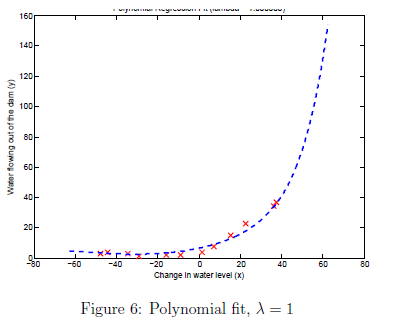

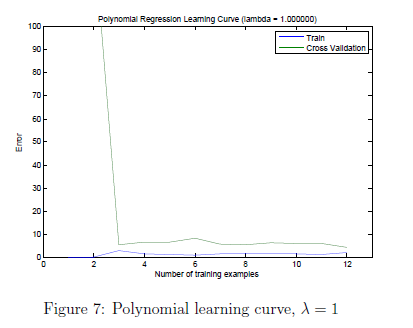

    For $\lambda= 1$, you should see a polynomial fit that follows the data trend well (Figure 6) and a learning curve (Figure 7) showing that both the cross validation and training error converge to a relatively low value. This shows the $\lambda= 1$ regularized polynomial regression model does not have the high bias or high-variance problems. In effect, it achieves a good trade-off between bias and variance.

    For $\lambda= 100$, you should see a polynomial fit (Figure 8) that does not follow the data well. In this case, there is too much regularization and the model is unable to fit the training data.

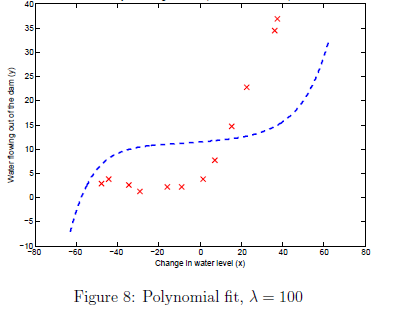

### 3.3 Selecting lambda using a cross validation set

From the previous parts of the exercise, you observed that the value of $\lambda$ can significantly affect the results of regularized polynomial regression on the training and cross validation set. In particular, a model without regularization ($\lambda = 0$) fits the training set well, but does not generalize. Conversely, a model with too much regularization ($\lambda=100$)  does not fit the training set and testing set well. A good choice of $\lambda$ (e.g. $\lambda=1$) can provide a good fit to the data.

    In this section, you will implement an automated method to select the parameter. Concretely, you will use a cross validation set to evaluate how good each $\lambda$ value is. After selecting the best $\lambda$ value using the cross validation set, we can then evaluate the model on the test set to estimate how well the model will perform on actual unseen data. Your task is to complete the code in `validationCurve.m`. Specifically, you should should use the `trainLinearReg` function to train the model using different values of $\lambda$ and compute the training error and cross validation error. The function will try $\lambda$ in the following range: {0, 0.001, 0.003, 0.01, 0.03, 0.1, 0.3, 1, 3, 10}.

    After you have completed the code, the code below will run your function and plot a cross validation curve of error v.s $\lambda$ that allows you select which $\lambda$ parameter to use. You should see a plot similar to Figure 9. 

[lambda_vec, error_train, error_val] = validationCurve(X_poly, y, X_poly_val, yval);
plot(lambda_vec, error_train, lambda_vec, error_val);
legend('Train', 'Cross Validation');
xlabel('lambda');
ylabel('Error');
for i = 1:length(lambda_vec)
    if i == 1
        fprintf('lambda\t\tTrain Error\tValidation Error\n');
    end
    fprintf('%f\t%f\t%f\n',lambda_vec(i), error_train(i), error_val(i));
end

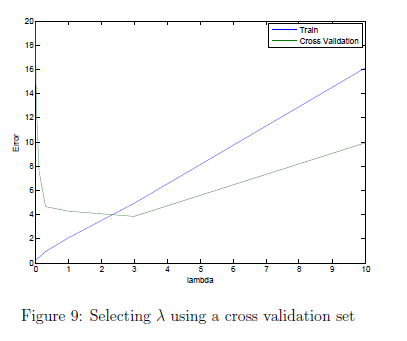

In this figure, we can see that the best value of $\lambda$ is around 3. Due to randomness in the training and validation splits of the dataset, the cross validation error can sometimes be lower than the training error. 

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 3.4 Optional (ungraded) exercise: Computing test set error

In the previous part of the exercise, you implemented code to compute the cross validation error for various values of the regularization parameter $\lambda$. However, to get a better indication of the model's performance in the real world, it is important to evaluate the 'final' model on a test set that was not used in any part of training (that is, it was neither used to select the $\lambda$ parameters, nor to learn the model parameters $\theta$).

    For this optional (ungraded) exercise, you should compute the test error using the best value of $\lambda$ you found. In our cross validation, we obtained a test error of 3.8599 for $\lambda= 3.$ You do not need to submit any solutions for this optional (ungraded) exercise.

%%%%%%%%% Add your code to compute the test error below %%%%%%%%%%%



### 3.5 Optional (ungraded) exercise: Plotting learning curves with randomly selected examples

In practice, especially for small training sets, when you plot learning curves to debug your algorithms, it is often helpful to average across multiple sets of randomly selected examples to determine the training error and cross validation error. Concretely, to determine the training error and cross validation error for $i$ examples, you should first randomly select $i$ examples from the training set and $i$ examples from the cross validation set. You will then learn the parameters $\theta$ using the randomly chosen training set and evaluate the parameters $\theta$ on the randomly chosen training set and cross validation set. The above steps should then be repeated multiple times (say 50) and the averaged error should be used to determine the training error and cross validation error for $i$ examples.

     For this optional (ungraded) exercise, you should implement the above strategy for computing the learning curves in `learningCurve.m` and use the code below to call your modified function and generate the plot.

lambda = 0.01;
[error_train, error_val] = learningCurve(X_poly, y, X_poly_val, yval, lambda);
plot(1:m, error_train, 1:m, error_val);

title(sprintf('Polynomial Regression Learning Curve (lambda = %f)', lambda));
xlabel('Number of training examples')
ylabel('Error')
axis([0 13 0 100])
legend('Train', 'Cross Validation')

For reference, Figure 10 shows the learning curve we obtained for polynomial regression with $\lambda= 0.01$. 

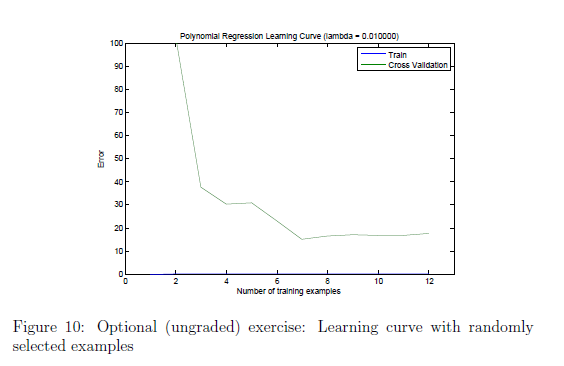

Your figure may differ slightly due to the random selection of examples. 

*You do not need to submit any solutions for this optional (ungraded) exercise.*

## Submission and Grading

After completing various parts of the assignment, be sure to use the submit function system to submit your solutions to our servers. The following is a breakdown of how each part of this exercise is scored.

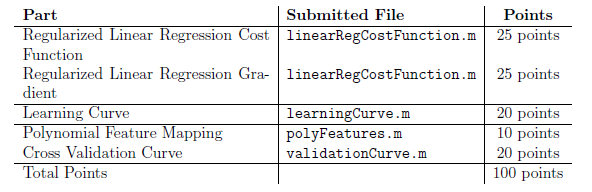

You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.